# **Chapter-4: Mobile Robot Localization**

Mobile robot localization is the process by which an autonomous robot estimates its position and orientation (pose) within an environment or map. It forms the foundation of navigation, enabling the robot to plan paths, make decisions, and execute tasks reliably.

## Learning Objectives

- Understand the **sources of localization uncertainty**, including sensor noise, sensor aliasing, and odometric (motion) errors 

- Explain how **uncertainty propagates over time** in robot motion and how it can be modeled using covariance and probabilistic representations 

- Apply fundamental probability concepts—**conditional probability, total probability, and Bayes’ rule**—to update robot position estimates 

- Interpret and implement the key components of **Markov localization**, including belief, prior, likelihood, prediction, and posterior 

- Analyze the roles of **motion models and sensor models** in shaping and correcting the belief distribution 

- Compare different **map representations (geometric, grid, topological, hybrid)** and understand their impact on localization accuracy and computational complexity

## The Challenge of Localization: Noise and Aliasing

Localization remains one of the most challenging aspects of autonomous navigation, primarily due to the presence of noise, uncertainty, and ambiguity in sensor and effector data. If an ideal, perfectly accurate Global Positioning System (GPS) were available, much of the localization problem would disappear. Such a GPS would instantly provide a robot’s exact position (indoors or outdoors) making the question *“Where am I?”* trivial. However, this ideal sensor does not exist. 

Sensor Noise: Sensors are the foundation of perception. The quality of a robot’s understanding of the world depends directly on the accuracy and consistency of its sensors. *Sensor noise refers to random variations in sensor readings under identical conditions, reducing the reliability and useful information content of the data. *

Sensor Aliasing: While noise introduces randomness, another major limitation is sensor aliasing which causes ambiguity. Sensor aliasing occurs when different environmental states produce identical sensor readings. Formally, aliasing represents a many-to-one mapping between environmental states and sensor readings. This ambiguity prevents the robot from determining its true position from a single observation. For example, with sonar sensing alone, a robot cannot distinguish whether an obstacle ahead is a human or a cardboard box, the same readings could correspond to either.

To overcome sensor aliasing, robots rely on sequences of observations combined over time. By integrating multiple readings through probabilistic or temporal filtering methods, sufficient information can be accumulated to infer the correct location.

Effector Noise: Localization uncertainty arises not only from perception but also from motion execution. Just as sensors are noisy, effectors (motors and actuators) are imprecise. Even when a robot commands a precise movement, the actual displacement may differ due to slippage, uneven terrain, wheel misalignment, or unmodeled dynamics. This phenomenon is often referred to as odometric error, the discrepancy between the robot’s estimated position (computed from wheel encoders or other proprioceptive sensors) and its true position. Because odometry integrates small errors over time, position uncertainty accumulates, making it unreliable for long-term localization. Common sources of odometric error include:

- Limited encoder resolution and integration step size

- Misaligned or unequal wheel diameters

- Variations in the wheel–ground contact point

- Slippage or non-planar surfaces

Some of these are **systematic errors** that can be reduced through careful calibration, while others are **random errors** that remain even after calibration.

## Error Model for Odometric Position Estimation

The pose of a differential-drive robot can be represented as $p=[x,y,\theta ]^T$ and updated incrementally based on the wheel displacements $\Delta s_r$ and $\Delta s_l$ : $\Delta x=\Delta s.cos(\theta +\frac{\Delta \theta }{2}), \; \Delta y=\Delta s.sins(\theta +\frac{\Delta \theta }{2})$ where, $\Delta s=\frac{\Delta s_r+\Delta s_l}{2}$ ; $\Delta \theta=\frac{\Delta s_r-\Delta s_l}{b}$ and b is the distance between the two wheels. Thus, the updated pose vector can be expressed as $p\prime =
\pmatrix{x+\Delta s.\cos(\theta +\frac{\Delta \theta }{2}) \cr y+\Delta s.\sin(\theta +\frac{\Delta \theta }{2}) \cr \theta +\Delta \theta }
$. Because motion errors accumulate over time, the uncertainty in the estimated pose increases. This uncertainty can be modeled using a **covariance matrix** that propagates error through successive motion updates $\sum _p^\prime =J_p\sum _p J_p^T + J_u\sum _u J_u^T$. Where $J
_p
	
$ and $J_u$ are the Jacobians with respect to the pose and control variables, respectively. Experimentally determining the **error constants** for a specific robot and environment allows the covariance to be tuned for accurate probabilistic localization (e.g., Kalman or particle filters). 

### Learning by Doing Exercise

Below is a MATLAB learning-by-doing activity built around **odometric error propagation** for a differential-drive robot as described above. After doing this exercise, you will learn to:

- propagate pose uncertainty using Jacobians and covariance, 

- compare that prediction with Monte Carlo simulation, 

- observe how uncertainty grows over time, 

- study the effect of wheel noise and turning motion.

**Part 1: Run the baseline simulation**

Run the code as given and observe

- the predicted mean trajectory, 

- the Monte Carlo mean trajectory, 

- the scatter of final robot poses, 

- the covariance ellipses, 

- the growth of Var(x),Var(y),Var(θ). 

**Answer the Questions**

- Does the Monte Carlo mean approximately match the covariance-propagated mean? 

- Which uncertainty grows faster: position or heading? 

- Is the final uncertainty roughly circular or elongated? 

- What does the shape of the ellipse tell you about directional uncertainty?

**Part 2: Straight motion vs turning motion**

Change:

`dsr_nom = 0.10;`

`dsl_nom = 0.10;`

This represents ideal straight-line motion.

Then compare with:

`dsr_nom = 0.10;`

`dsl_nom = 0.08;`

This produces a turn.

**Answer the Questions**

- In which case does heading uncertainty grow faster? 

- Which motion produces a more spread-out final position cloud? 

- Why does turning couple orientation error into position error more strongly?

**Part 3: Increase wheel noise**

Double the noise constants:

`kr = 0.10;`

`kl = 0.10;`

**Answer the Questions**

- How does doubling encoder noise affect the covariance ellipse size? 

- Is the increase in uncertainty linear, sublinear (increases slower than linear), or superlinear (increases faster than linear) over time? 

- Which state variable is most sensitive to wheel noise?

**Part 4: Unequal wheel noise**

Set different noise levels:

`kr = 0.02;`

`kl = 0.10;`

**Answer the Questions**

- Does the robot become more uncertain in heading? 

- Why does unequal uncertainty in the two wheels particularly affect rotation? 

- How does this asymmetry change the final trajectory cloud?

**Part 5: Initial pose uncertainty**

Increase the initial uncertainty:

`Sigma0 = diag([0.05^2, 0.05^2, deg2rad(5)^2]);`

**Answer the Questions**

- How much of the final error comes from initial uncertainty versus motion noise? 

- When the initial heading is uncertain, why does future position uncertainty also grow? 

- In practical localization, why is it important to reduce both initial pose uncertainty and odometric noise?

**Part 6: Interpret the Jacobians**

Focus on these two matrices:

- $J_{p\;}$: sensitivity of the next pose to current pose, 

- $J_u$: sensitivity of the next pose to wheel displacement errors. 

**Questions**

- Why does $J_{p\;}$ contain terms involving $\textrm{ds}\;\sin \;\phi \;$and $\textrm{ds}\;\cos \;\phi$? 

- Why does $J_u$ show that both wheel errors affect both position and orientation? 

- Under what condition would control uncertainty mainly affect heading rather than translation?

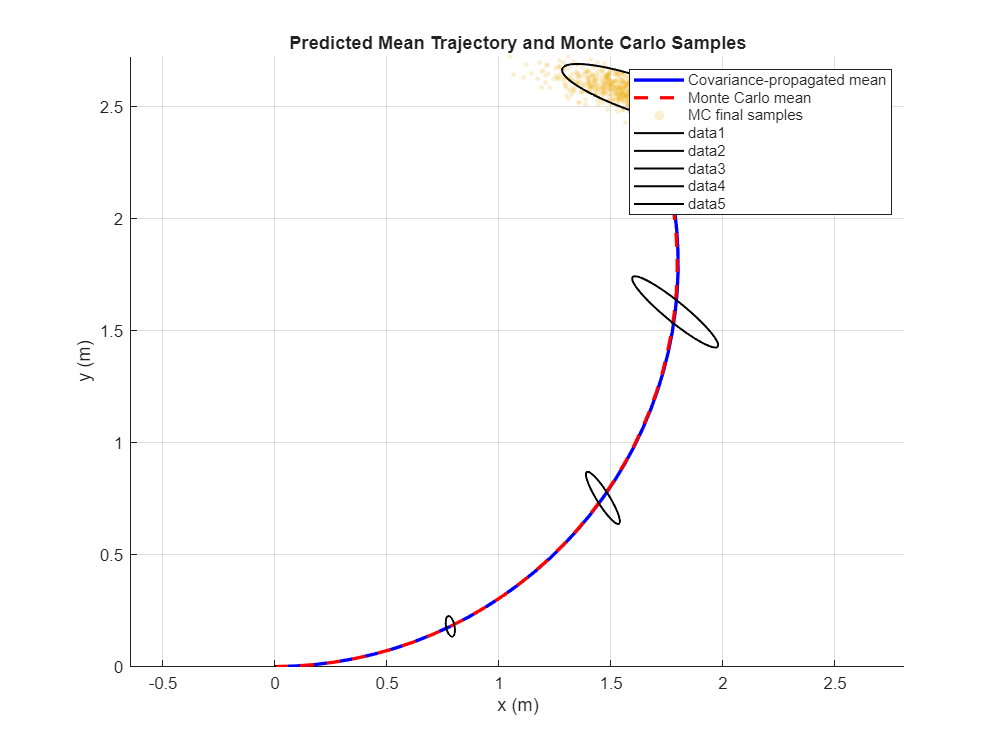

%% Odometric Error Propagation for a Differential-Drive Robot
% This script demonstrates how uncertainty in wheel motions propagates
% into uncertainty in robot pose using covariance propagation.
%
% State: p = [x; y; theta]
% Control: u = [ds_r; ds_l]
%
% Motion model:
% ds     = (ds_r + ds_l)/2
% dtheta = (ds_r - ds_l)/b
% x'     = x + ds*cos(theta + dtheta/2)
% y'     = y + ds*sin(theta + dtheta/2)
% theta' = theta + dtheta
%
% Covariance propagation:
% Sigma_p_next = Jp * Sigma_p * Jp' + Ju * Sigma_u * Ju'

com.mathworks.services.Prefs.setBooleanPref('LiveEditorFigureVisible', false);
clear; clc; close all;

%% -------------------------------
% PARAMETERS
%% -------------------------------
b = 0.4;                 % wheelbase (m)
N = 40;                  % number of motion steps

% Initial pose
p0 = [0; 0; 0];          % [x; y; theta]
Sigma0 = diag([0.001^2, 0.001^2, deg2rad(0.5)^2]);

% Nominal wheel displacements for each step
% Try changing these values to study straight motion vs turning
dsr_nom = 0.10;          % right wheel displacement per step (m)
dsl_nom = 0.08;          % left wheel displacement per step (m)

% Wheel-motion noise model
% Assume uncertainty in wheel displacement grows with motion magnitude
kr = 0.05;               % right wheel proportional noise constant
kl = 0.05;               % left wheel proportional noise constant
sigma_r = kr * abs(dsr_nom);
sigma_l = kl * abs(dsl_nom);

Sigma_u = diag([sigma_r^2, sigma_l^2]);   % control covariance

% Monte Carlo settings
M = 1000;                % number of simulated trials

%% -------------------------------
% STORAGE
%% -------------------------------
p_mean = zeros(3, N+1);          
Sigma_all = zeros(3, 3, N+1);    

p_mean(:,1) = p0;
Sigma_all(:,:,1) = Sigma0;

% For Monte Carlo
P_mc = zeros(3, M, N+1);
for k = 1:M
    P_mc(:,k,1) = p0;
end

%% -------------------------------
% MAIN LOOP: COVARIANCE PROPAGATION
%% -------------------------------
for k = 1:N
    
    p = p_mean(:,k);
    x = p(1); y = p(2); th = p(3);

    dsr = dsr_nom;
    dsl = dsl_nom;

    ds = (dsr + dsl)/2;
    dth = (dsr - dsl)/b;
    phi = th + dth/2;

    p_next = [x + ds*cos(phi);
              y + ds*sin(phi);
              th + dth];

    Jp = [1, 0, -ds*sin(phi);
          0, 1,  ds*cos(phi);
          0, 0,  1];

    dds_dsr = 1/2;
    dds_dsl = 1/2;
    dphi_dsr = 1/(2*b);
    dphi_dsl = -1/(2*b);

    dx_dsr = dds_dsr*cos(phi) - ds*sin(phi)*dphi_dsr;
    dx_dsl = dds_dsl*cos(phi) - ds*sin(phi)*dphi_dsl;

    dy_dsr = dds_dsr*sin(phi) + ds*cos(phi)*dphi_dsr;
    dy_dsl = dds_dsl*sin(phi) + ds*cos(phi)*dphi_dsl;

    Ju = [dx_dsr, dx_dsl;
          dy_dsr, dy_dsl;
          1/b, -1/b];

    Sigma_next = Jp * Sigma_all(:,:,k) * Jp' + Ju * Sigma_u * Ju';

    p_mean(:,k+1) = p_next;
    Sigma_all(:,:,k+1) = Sigma_next;

    %% ---------------------------
    % MONTE CARLO SIMULATION
    %% ---------------------------
    for m = 1:M
        p_mc = P_mc(:,m,k);
        x_mc = p_mc(1); y_mc = p_mc(2); th_mc = p_mc(3);

        dsr_s = dsr_nom + sigma_r*randn;
        dsl_s = dsl_nom + sigma_l*randn;

        ds_s = (dsr_s + dsl_s)/2;
        dth_s = (dsr_s - dsl_s)/b;
        phi_s = th_mc + dth_s/2;

        P_mc(:,m,k+1) = [x_mc + ds_s*cos(phi_s);
                         y_mc + ds_s*sin(phi_s);
                         th_mc + dth_s];
    end
end

%% -------------------------------
% EXTRACT MONTE CARLO STATISTICS
%% -------------------------------
mc_mean = zeros(3, N+1);
mc_cov = zeros(3,3,N+1);

for k = 1:N+1
    X = squeeze(P_mc(:,:,k));
    mc_mean(:,k) = mean(X,2);
    mc_cov(:,:,k) = cov(X');
end

%% -------------------------------
% PLOTS: TRAJECTORY
%% -------------------------------
f1 = figure('Name','Odometry Trajectory', ...
            'WindowStyle','normal', ...
            'Position',[100 100 800 600], ...
            'Color','w');
set(f1,'Visible','on');

ax1 = axes('Parent',f1);
hold(ax1,'on'); grid(ax1,'on'); axis(ax1,'equal');

title(ax1,'Predicted Mean Trajectory and Monte Carlo Samples');
xlabel(ax1,'x (m)');
ylabel(ax1,'y (m)');

plot(ax1,p_mean(1,:), p_mean(2,:), 'b-', 'LineWidth', 2);
plot(ax1,mc_mean(1,:), mc_mean(2,:), 'r--', 'LineWidth', 2);

scatter(ax1,P_mc(1,:,end), P_mc(2,:,end), 8, 'filled', ...
    'MarkerFaceAlpha', 0.2, 'MarkerEdgeAlpha', 0.2);

legend(ax1,'Covariance-propagated mean', 'Monte Carlo mean', 'MC final samples');

steps_to_plot = [1, 10, 20, 30, 41];
for idx = 1:length(steps_to_plot)
    k = steps_to_plot(idx);
    plot_cov_ellipse_2d(p_mean(1:2,k), Sigma_all(1:2,1:2,k), 2);
end

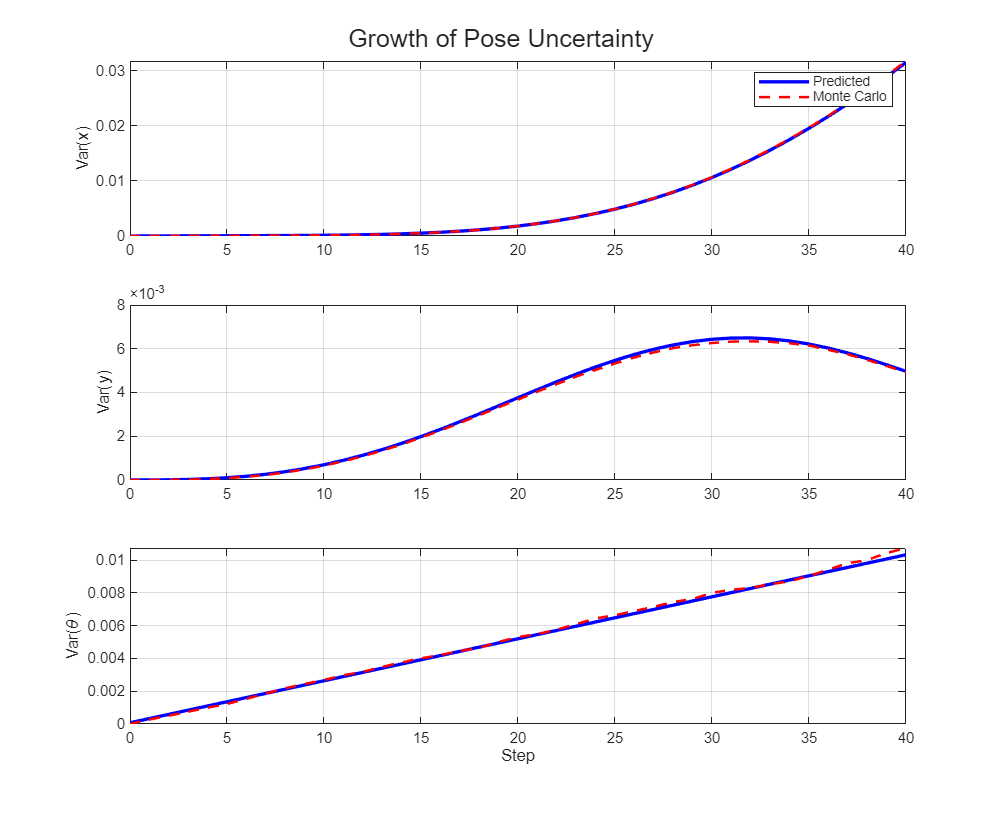


%% -------------------------------
% PLOTS: VARIANCE GROWTH
%% -------------------------------
f2 = figure('Name','Uncertainty Growth', ...
            'WindowStyle','normal', ...
            'Position',[950 100 800 650], ...
            'Color','w');
set(f2,'Visible','on');

subplot(3,1,1,'Parent',f2);
plot(0:N, squeeze(Sigma_all(1,1,:)), 'b-', 'LineWidth', 2); hold on;
plot(0:N, squeeze(mc_cov(1,1,:)), 'r--', 'LineWidth', 1.5);
grid on;
ylabel('Var(x)');
legend('Predicted', 'Monte Carlo');

subplot(3,1,2,'Parent',f2);
plot(0:N, squeeze(Sigma_all(2,2,:)), 'b-', 'LineWidth', 2); hold on;
plot(0:N, squeeze(mc_cov(2,2,:)), 'r--', 'LineWidth', 1.5);
grid on;
ylabel('Var(y)');

subplot(3,1,3,'Parent',f2);
plot(0:N, squeeze(Sigma_all(3,3,:)), 'b-', 'LineWidth', 2); hold on;
plot(0:N, squeeze(mc_cov(3,3,:)), 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Step');
ylabel('Var(\theta)');

sgtitle('Growth of Pose Uncertainty');


%% -------------------------------
% DISPLAY FINAL RESULTS
%% -------------------------------
disp('Final predicted mean pose:');

Final predicted mean pose:


disp(p_mean(:,end));

    1.6369
    2.5493
    2.0000




disp('Final Monte Carlo mean pose:');

Final Monte Carlo mean pose:


disp(mc_mean(:,end));

    1.6339
    2.5426
    1.9987




disp('Final predicted covariance:');

Final predicted covariance:


disp(Sigma_all(:,:,end));

    0.0315   -0.0101   -0.0161
   -0.0101    0.0050    0.0042
   -0.0161    0.0042    0.0103




disp('Final Monte Carlo covariance:');

Final Monte Carlo covariance:


disp(mc_cov(:,:,end));

    0.0317   -0.0098   -0.0165
   -0.0098    0.0049    0.0041
   -0.0165    0.0041    0.0107




%% -------------------------------
% LOCAL FUNCTION: 2D covariance ellipse
%% -------------------------------
function plot_cov_ellipse_2d(mu, Sigma, nsig)
    [V,D] = eig(Sigma);
    t = linspace(0, 2*pi, 100);
    circle = [cos(t); sin(t)];
    ellipse = nsig * V * sqrt(D) * circle;
    ellipse = ellipse + mu;
    plot(ellipse(1,:), ellipse(2,:), 'k-', 'LineWidth', 1.2);
end

Odometry estimates pose from wheel displacements, but wheel motions are never exact. Small encoder errors, slip, uneven ground, and modeling inaccuracies introduce uncertainty. At each step, that uncertainty is mapped into pose uncertainty through the robot’s motion model. Because each new pose depends on the previous one, the uncertainty accumulates over time.

The covariance update ${\Sigma \;}_p^+ =J_p \Sigma_p J_p^T +J_u \Sigma_u J_u^T$ has two parts: $J_p \Sigma_p J_p^T$carries forward the old pose uncertainty while $J_u \Sigma_u J_u^T$adds new uncertainty from wheel motion errors. This is why odometry alone gradually drifts and must eventually be corrected using external sensing such as landmarks, GPS, IMU, LiDAR, or camera measurements.

# **Localization-Based Navigation Versus Programmed Solutions**

A mobile robot requires sensors for perception and motion control for actuation. However, the need for an explicit **localization system** depends on the navigation strategy employed. Two principal approaches exist, which are **behavior-based navigation** and **map-based (model-based) navigation**. 

**Behavior-Based Navigation: **Behavior-based navigation avoids explicit localization and map-building. Instead, the robot relies on a set of reactive behaviors, such as wall-following, obstacle avoidance, or goal detection, coordinated to achieve navigation objectives. This approach offers simplicity, fast implementation, and robustness in constrained environments. However, it has key limitations:

- Poor scalability to new or large environments

- High dependence on robot hardware and environmental conditions

- Difficult tuning when multiple behaviors interact

**Map-Based Navigation: **Map-based navigation incorporates localization, mapping, and planning within a unified architecture. The robot maintains a belief about its position relative to a map, updating it through sensor observations. Key advantages include:

- Explicit position estimation and transparency to human operators

- Transferability across environments via reusable maps

- Cognitive planning using environmental representation

Its main drawbacks are greater computational complexity and dependence on model accuracy. Divergence between the internal map and real-world conditions can degrade performance.

In map-based localization, a robot must represent two key elements:

- **A map of the environment** — describing relevant spatial features at a chosen level of fidelity.

- **A belief about the robot's own position within that map** — expressing how certain the robot is about where it is located in the map.

Decisions about how these two representations determine the complexity, computational cost, and accuracy of the localization system. Before we delve deeper let's spend some time on understanding the basics of maps and belief.

### Map Representation

Map fidelity constrains the fidelity of pose estimates and vice-versa. Three design principles should guide the choice of map representation:

- **Match goal precision:** Map precision must be sufficient for the tasks and goals the robot must achieve.

- **Match sensor modality:** Map features should reflect what the robot’s sensors reliably detect (range, lines, landmarks, images, etc.).

- **Match computational budget:** Richer maps increase reasoning, storage, and update costs.

Map representations commonly fall into three broad classes:

**1. Continuous (geometric) representations: **A continuous or geometric map represents the environment using precise spatial coordinates such as points, lines, and polygons. It provides high accuracy and is well suited for tasks requiring detailed geometric information. Continuous maps are often used with sensors like laser rangefinders that can extract exact features such as walls or corners. However, their main drawback lies in the high computational cost of construction and maintenance, especially in large or complex environments.

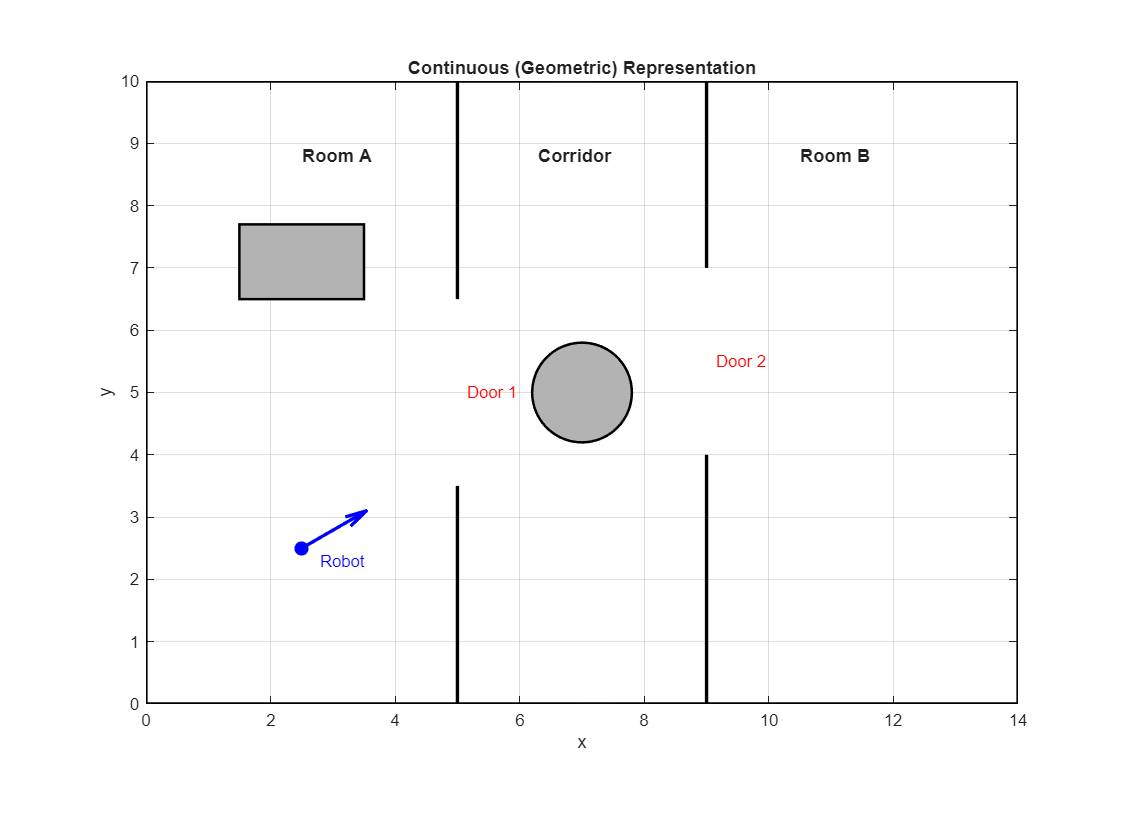

com.mathworks.services.Prefs.setBooleanPref('LiveEditorFigureVisible', false);
clear; clc; close all;

%% ✅ FORCE EXTERNAL WINDOW
f = figure('Name','Continuous Geometric Map', ...
           'WindowStyle','normal', ...
           'Position',[100 100 900 650], ...
           'Color','w');

set(f,'Visible','on');

ax = axes('Parent',f);
hold(ax,'on'); 
axis(ax,'equal');

xlim(ax,[0 14]); 
ylim(ax,[0 10]);

title(ax,'Continuous (Geometric) Representation');
xlabel(ax,'x'); 
ylabel(ax,'y');

%% Outer boundary
plot([0 14 14 0 0], [0 0 10 10 0], 'k-', 'LineWidth', 2);

%% Internal walls with door openings
% Left room to corridor wall
plot([5 5], [0 3.5], 'k-', 'LineWidth', 2);
plot([5 5], [6.5 10], 'k-', 'LineWidth', 2);

% Corridor to right room wall
plot([9 9], [0 4], 'k-', 'LineWidth', 2);
plot([9 9], [7 10], 'k-', 'LineWidth', 2);

%% Obstacles
% Rectangular obstacle in left room
rectangle('Position', [1.5 6.5 2 1.2], ...
          'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'k', 'LineWidth', 1.5);

% Circular obstacle in corridor
theta = linspace(0, 2*pi, 200);
cx = 7; cy = 5; r = 0.8;
fill(cx + r*cos(theta), cy + r*sin(theta), [0.7 0.7 0.7], ...
     'EdgeColor', 'k', 'LineWidth', 1.5);

%% Robot pose
xr = 2.5; yr = 2.5; th = pi/6;
plot(xr, yr, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
quiver(xr, yr, cos(th), sin(th), 1.2, 'b', 'LineWidth', 2, 'MaxHeadSize', 1);

%% Labels
text(2.5, 8.8, 'Room A', 'FontSize', 11, 'FontWeight', 'bold');
text(6.3, 8.8, 'Corridor', 'FontSize', 11, 'FontWeight', 'bold');
text(10.5, 8.8, 'Room B', 'FontSize', 11, 'FontWeight', 'bold');
text(5.15, 5.0, 'Door 1', 'Color', 'r', 'FontSize', 10);
text(9.15, 5.5, 'Door 2', 'Color', 'r', 'FontSize', 10);
text(xr+0.3, yr-0.2, 'Robot', 'Color', 'b', 'FontSize', 10);

grid on;
box on;

**2. Decomposition / grid representations: **In a grid or occupancy map, the environment is divided into a uniform grid of cells, each storing the probability of being occupied or free. This discrete representation is directly compatible with range-based sensors and allows straightforward map updating from sensor data. It is one of the most widely used representations for mobile robots due to its simplicity and effectiveness. The main limitation is memory consumption, as the number of cells grows rapidly with map size and resolution also grows.

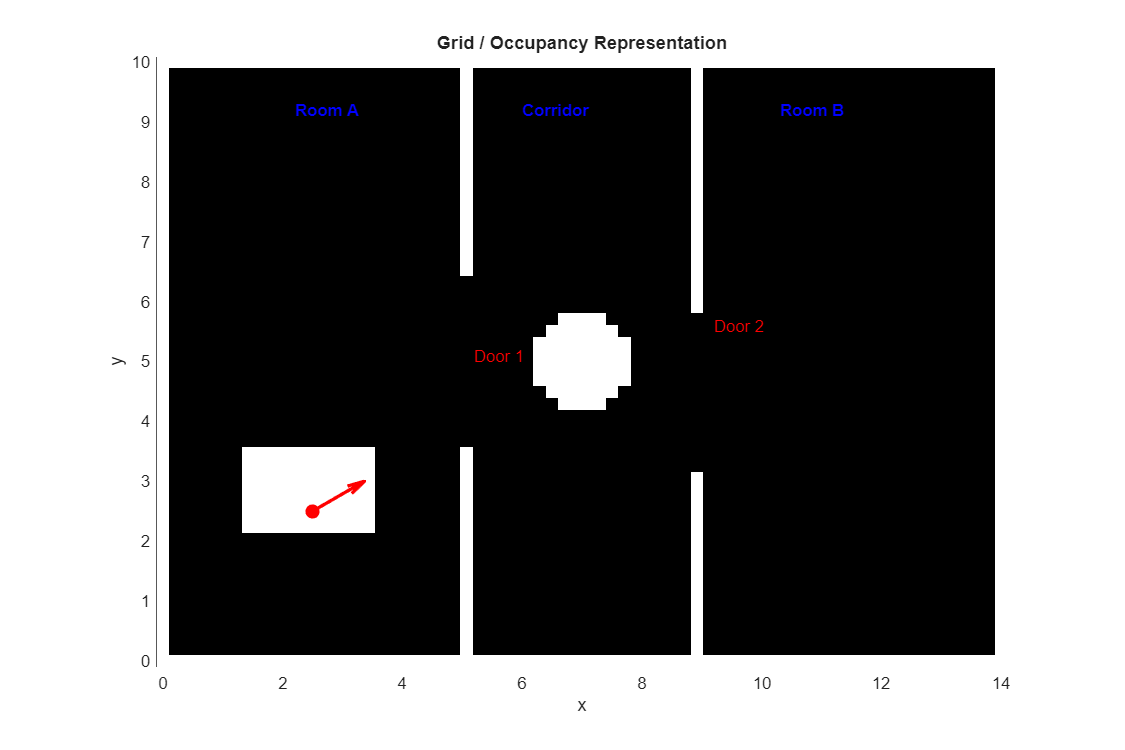

com.mathworks.services.Prefs.setBooleanPref('LiveEditorFigureVisible', false);
clear; clc; close all;

%% Grid settings
Nx = 70;   % columns
Ny = 50;   % rows
xmax = 14;
ymax = 10;

occ = zeros(Ny, Nx);   % 0 = free, 1 = occupied

% Helper conversion from world coordinates to grid indices
x_to_col = @(x) max(1, min(Nx, round((x / xmax) * (Nx-1)) + 1));
y_to_row = @(y) max(1, min(Ny, round((y / ymax) * (Ny-1)) + 1));

%% Outer boundary walls
occ(1,:)   = 1;
occ(end,:) = 1;
occ(:,1)   = 1;
occ(:,end) = 1;

%% Internal walls with door openings
c5 = x_to_col(5);
c9 = x_to_col(9);

r0   = y_to_row(0);
r35  = y_to_row(3.5);
r40  = y_to_row(4);
r65  = y_to_row(6.5);
r70  = y_to_row(7);
r10  = y_to_row(10);

% Since image rows go top-down, sort ranges
rows1 = sort([r0 r35]);
rows2 = sort([r65 r10]);
rows3 = sort([r0 r40]);
rows4 = sort([r70 r10]);

occ(rows1(1):rows1(2), c5) = 1;
occ(rows2(1):rows2(2), c5) = 1;
occ(rows3(1):rows3(2), c9) = 1;
occ(rows4(1):rows4(2), c9) = 1;

%% Rectangular obstacle
x1 = x_to_col(1.5); x2 = x_to_col(3.5);
y1 = y_to_row(6.5); y2 = y_to_row(7.7);
rr = sort([y1 y2]);
cc = sort([x1 x2]);
occ(rr(1):rr(2), cc(1):cc(2)) = 1;

%% Circular obstacle
[Xg, Yg] = meshgrid(linspace(0, xmax, Nx), linspace(0, ymax, Ny));
circleMask = (Xg - 7).^2 + (Yg - 5).^2 <= 0.8^2;
occ(circleMask) = 1;

%% Plot occupancy map (EXTERNAL WINDOW)
f = figure('Name','Occupancy Grid Map', ...
           'WindowStyle','normal', ...
           'Position',[100 100 900 600], ...
           'Color','w');

set(f,'Visible','on');

ax = axes('Parent',f);
hold(ax,'on');

imagesc(ax,[0 xmax], [0 ymax], flipud(occ));
axis(ax,'equal'); 
axis(ax,'tight');
colormap(ax,gray);
set(ax,'YDir','normal');

title(ax,'Grid / Occupancy Representation');
xlabel(ax,'x'); 
ylabel(ax,'y');

%% Robot position
xr = 2.5; yr = 2.5; th = pi/6;
plot(ax,xr, yr, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
quiver(ax,xr, yr, cos(th), sin(th), 1.0, 'r', 'LineWidth', 2, 'MaxHeadSize', 1);

%% Labels
text(ax,2.2, 9.2, 'Room A', 'Color', 'b', 'FontWeight', 'bold');
text(ax,6.0, 9.2, 'Corridor', 'Color', 'b', 'FontWeight', 'bold');
text(ax,10.3, 9.2, 'Room B', 'Color', 'b', 'FontWeight', 'bold');
text(ax,5.2, 5.1, 'Door 1', 'Color', 'r');
text(ax,9.2, 5.6, 'Door 2', 'Color', 'r');

grid(ax,'on');

**3. Topological representations: **A topological map represents the environment as a network of nodes and edges, where nodes correspond to recognizable places and edges denote possible paths or connections between them. This approach focuses on connectivity rather than geometric detail, making it compact and efficient for navigation in large environments. It is particularly useful when the robot can identify distinct landmarks or locations. However, it lacks metric precision and is less effective for tasks requiring exact position control.

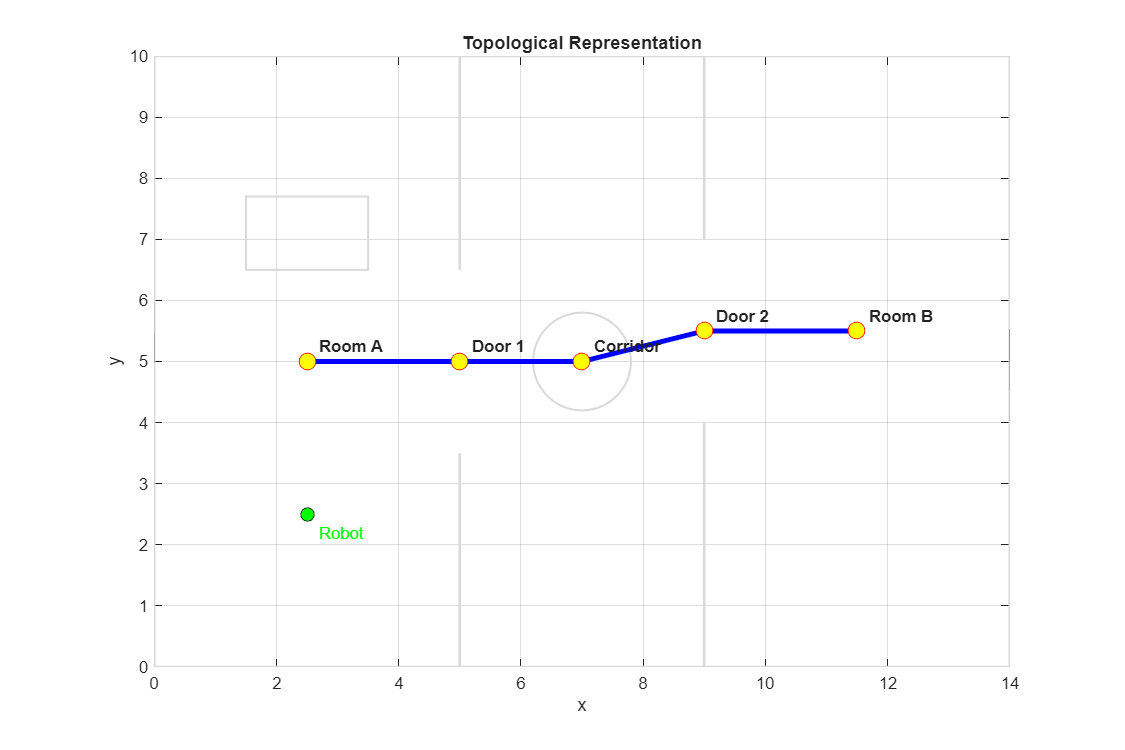

com.mathworks.services.Prefs.setBooleanPref('LiveEditorFigureVisible', false);
clear; clc; close all;

%% FIGURE (external window)
f = figure('Name','Topological Representation', ...
           'WindowStyle','normal', ...
           'Position',[100 100 900 600], ...
           'Color','w');

set(f,'Visible','on');

ax = axes('Parent',f);
hold(ax,'on'); 
axis(ax,'equal');

xlim(ax,[0 14]); 
ylim(ax,[0 10]);

title(ax,'Topological Representation');
xlabel(ax,'x'); 
ylabel(ax,'y');

%% Draw faint underlying geometry for reference
plot(ax,[0 14 14 0 0], [0 0 10 10 0], 'Color', [0.85 0.85 0.85], 'LineWidth', 1.5);

plot(ax,[5 5], [0 3.5], '-', 'Color', [0.85 0.85 0.85], 'LineWidth', 1.5);
plot(ax,[5 5], [6.5 10], '-', 'Color', [0.85 0.85 0.85], 'LineWidth', 1.5);

plot(ax,[9 9], [0 4], '-', 'Color', [0.85 0.85 0.85], 'LineWidth', 1.5);
plot(ax,[9 9], [7 10], '-', 'Color', [0.85 0.85 0.85], 'LineWidth', 1.5);

rectangle(ax,'Position', [1.5 6.5 2 1.2], ...
          'FaceColor', 'none', 'EdgeColor', [0.85 0.85 0.85], 'LineWidth', 1.2);

theta = linspace(0, 2*pi, 100);
plot(ax,7 + 0.8*cos(theta), 5 + 0.8*sin(theta), ...
     'Color', [0.85 0.85 0.85], 'LineWidth', 1.2);

%% Define topological nodes
nodes = [2.5 5.0;
         5.0 5.0;
         7.0 5.0;
         9.0 5.5;
         11.5 5.5];

labels = {'Room A', 'Door 1', 'Corridor', 'Door 2', 'Room B'};

%% Define edges
edges = [1 2;
         2 3;
         3 4;
         4 5];

%% Plot edges
for k = 1:size(edges,1)
    i = edges(k,1);
    j = edges(k,2);
    plot(ax,[nodes(i,1) nodes(j,1)], ...
             [nodes(i,2) nodes(j,2)], ...
         'b-', 'LineWidth', 3);
end

%% Plot nodes
plot(ax,nodes(:,1), nodes(:,2), 'ro', ...
     'MarkerSize', 10, 'MarkerFaceColor', 'y');

for i = 1:size(nodes,1)
    text(ax,nodes(i,1)+0.2, nodes(i,2)+0.25, ...
         labels{i}, 'FontSize', 10, 'FontWeight', 'bold');
end

%% Robot associated with nearest node / place
xr = 2.5; yr = 2.5;
plot(ax,xr, yr, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
text(ax,xr+0.2, yr-0.3, 'Robot', 'Color', 'g', 'FontSize', 10);

grid(ax,'on');
box(ax,'on');

**4. Hybrid (Metric–Topological) Map: **Hybrid maps combine the precision of local metric representations with the scalability of topological structures. The environment is divided into local areas, each modeled with detailed geometry, while the overall connectivity between areas is stored in a topological graph. This approach balances computational efficiency and localization accuracy, making it ideal for large-scale autonomous navigation systems.

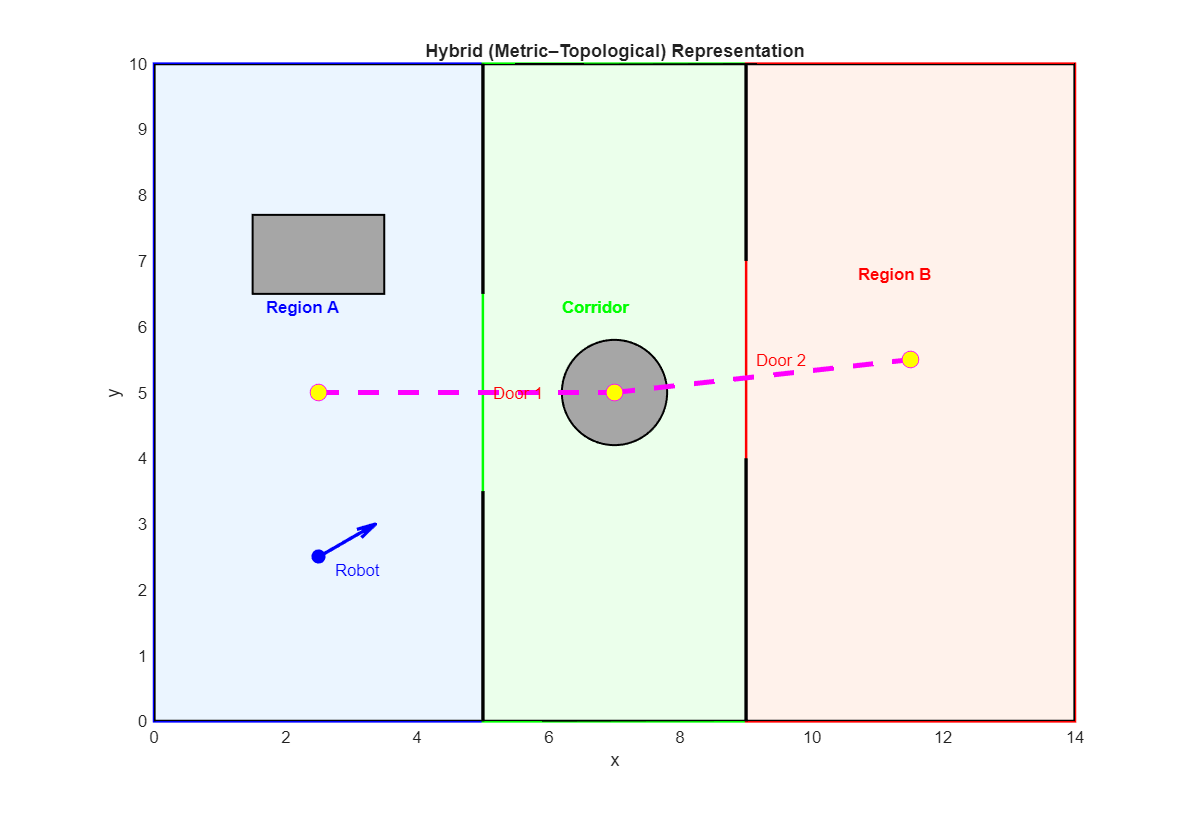

com.mathworks.services.Prefs.setBooleanPref('LiveEditorFigureVisible', false);
clear; clc; close all;

%% FIGURE (external window)
f = figure('Name','Hybrid (Metric–Topological) Representation', ...
           'WindowStyle','normal', ...
           'Position',[100 100 950 650], ...
           'Color','w');

set(f,'Visible','on');

ax = axes('Parent',f);
hold(ax,'on'); 
axis(ax,'equal');

xlim(ax,[0 14]); 
ylim(ax,[0 10]);

title(ax,'Hybrid (Metric–Topological) Representation');
xlabel(ax,'x'); 
ylabel(ax,'y');

%% Define three local metric regions
fill(ax,[0 5 5 0], [0 0 10 10], [0.92 0.96 1.0], 'EdgeColor', 'b', 'LineWidth', 1.5);
fill(ax,[5 9 9 5], [0 0 10 10], [0.92 1.0 0.92], 'EdgeColor', 'g', 'LineWidth', 1.5);
fill(ax,[9 14 14 9], [0 0 10 10], [1.0 0.95 0.92], 'EdgeColor', 'r', 'LineWidth', 1.5);

%% Overlay actual internal geometry
plot(ax,[0 14 14 0 0], [0 0 10 10 0], 'k-', 'LineWidth', 2);

plot(ax,[5 5], [0 3.5], 'k-', 'LineWidth', 2);
plot(ax,[5 5], [6.5 10], 'k-', 'LineWidth', 2);

plot(ax,[9 9], [0 4], 'k-', 'LineWidth', 2);
plot(ax,[9 9], [7 10], 'k-', 'LineWidth', 2);

rectangle(ax,'Position', [1.5 6.5 2 1.2], ...
          'FaceColor', [0.65 0.65 0.65], 'EdgeColor', 'k', 'LineWidth', 1.2);

theta = linspace(0, 2*pi, 200);
fill(ax,7 + 0.8*cos(theta), 5 + 0.8*sin(theta), [0.65 0.65 0.65], ...
     'EdgeColor', 'k', 'LineWidth', 1.2);

%% Topological graph over regions
regionCenters = [2.5 5.0;
                 7.0 5.0;
                 11.5 5.5];

plot(ax,[regionCenters(1,1) regionCenters(2,1)], ...
         [regionCenters(1,2) regionCenters(2,2)], ...
     'm--', 'LineWidth', 3);

plot(ax,[regionCenters(2,1) regionCenters(3,1)], ...
         [regionCenters(2,2) regionCenters(3,2)], ...
     'm--', 'LineWidth', 3);

plot(ax,regionCenters(:,1), regionCenters(:,2), 'mo', ...
     'MarkerSize', 10, 'MarkerFaceColor', 'y');

text(ax,regionCenters(1,1)-0.8, regionCenters(1,2)+1.3, 'Region A', 'FontWeight', 'bold', 'Color', 'b');
text(ax,regionCenters(2,1)-0.8, regionCenters(2,2)+1.3, 'Corridor', 'FontWeight', 'bold', 'Color', 'g');
text(ax,regionCenters(3,1)-0.8, regionCenters(3,2)+1.3, 'Region B', 'FontWeight', 'bold', 'Color', 'r');

%% Doors
text(ax,5.15, 5.0, 'Door 1', 'Color', 'r', 'FontSize', 10);
text(ax,9.15, 5.5, 'Door 2', 'Color', 'r', 'FontSize', 10);

%% Robot pose
xr = 2.5; yr = 2.5; th = pi/6;
plot(ax,xr, yr, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
quiver(ax,xr, yr, cos(th), sin(th), 1.0, 'b', 'LineWidth', 2, 'MaxHeadSize', 1);

text(ax,xr+0.25, yr-0.2, 'Robot', 'Color', 'b', 'FontSize', 10);

grid(ax,'on');
box(ax,'on');

### Review of Probability Theory

Let X be a random variable and x a specific value that X can assume. The probability that X takes the value x is written as $p(X=x)$ or simply $p(x).$ In the discrete case, probabilities sum to one: $\sum_x p(x) = 1$, while in the continuous case, the probability density function (PDF) satisfies $\int p(x)dx=1,$ in both cases, probabilities are non-negative, $p(x)\ge 0.$ A common continuous probability distribution is the Gaussian, defined as $p(x)= \frac{1}{\sqrt{2 \pi \sigma}}exp(-\frac{(x-\mu)^2}{2 \sigma ^2})$ where $\mu $ is the mean and $\sigma ^2$ is the variance. This is abbreviated as $p(x)= \mathcal{N}(\mu ,\sigma ^2)$. 

**Conditional Probability: **The joint probability of two variables $X$ and $Y$ is $p(x,y)$, representing the probability that both events occur. If $X$ and $Y$ are independent, their joint probability is given as $p(x,y)=p(x)p(y)$. The conditional probability $p(x|y)$ expresses the probability of $X=x$ given that $Y=y,$ and is defined as $p(x|y)= \frac{p(x,y)}{p(y)}$. 

**Theorem of Total Probability: **The total probability theorem allows computing $p\left(x\right)$ by marginalizing over all possible values of another variable $y$: $p(x)= \sum_y p(x|y)p(y)$  (for discrete case), or $p(x)= \int p(x|y)p(y) dy$ (for continuous case).

**Bayes’ Rule: **Bayes’ rule relates the conditional probabilities $p(x|y)$ and $p(y|x):$ $p(x|y)= \frac{p(y|x)p(x)}{p(y)}$. Since $p(y)$ is independent of $x,$ it often acts as a normalization factor, denoted by $𝜂,$ ensuring the total probability integrates to one: $p(x|y)=\eta p(y|x)p(x)$. Bayes’ rule forms the mathematical foundation for the perception (measurement) update in probabilistic localization. 

#### Learning by Doing Exercise

Consider a robot moving in a **1D corridor** with 5 possible cells: $x=\left\lbrace 1,2,3,4,5\right\rbrace \ldotp \;$We do not know its exact position. Instead, we assign **probabilities** to each position.

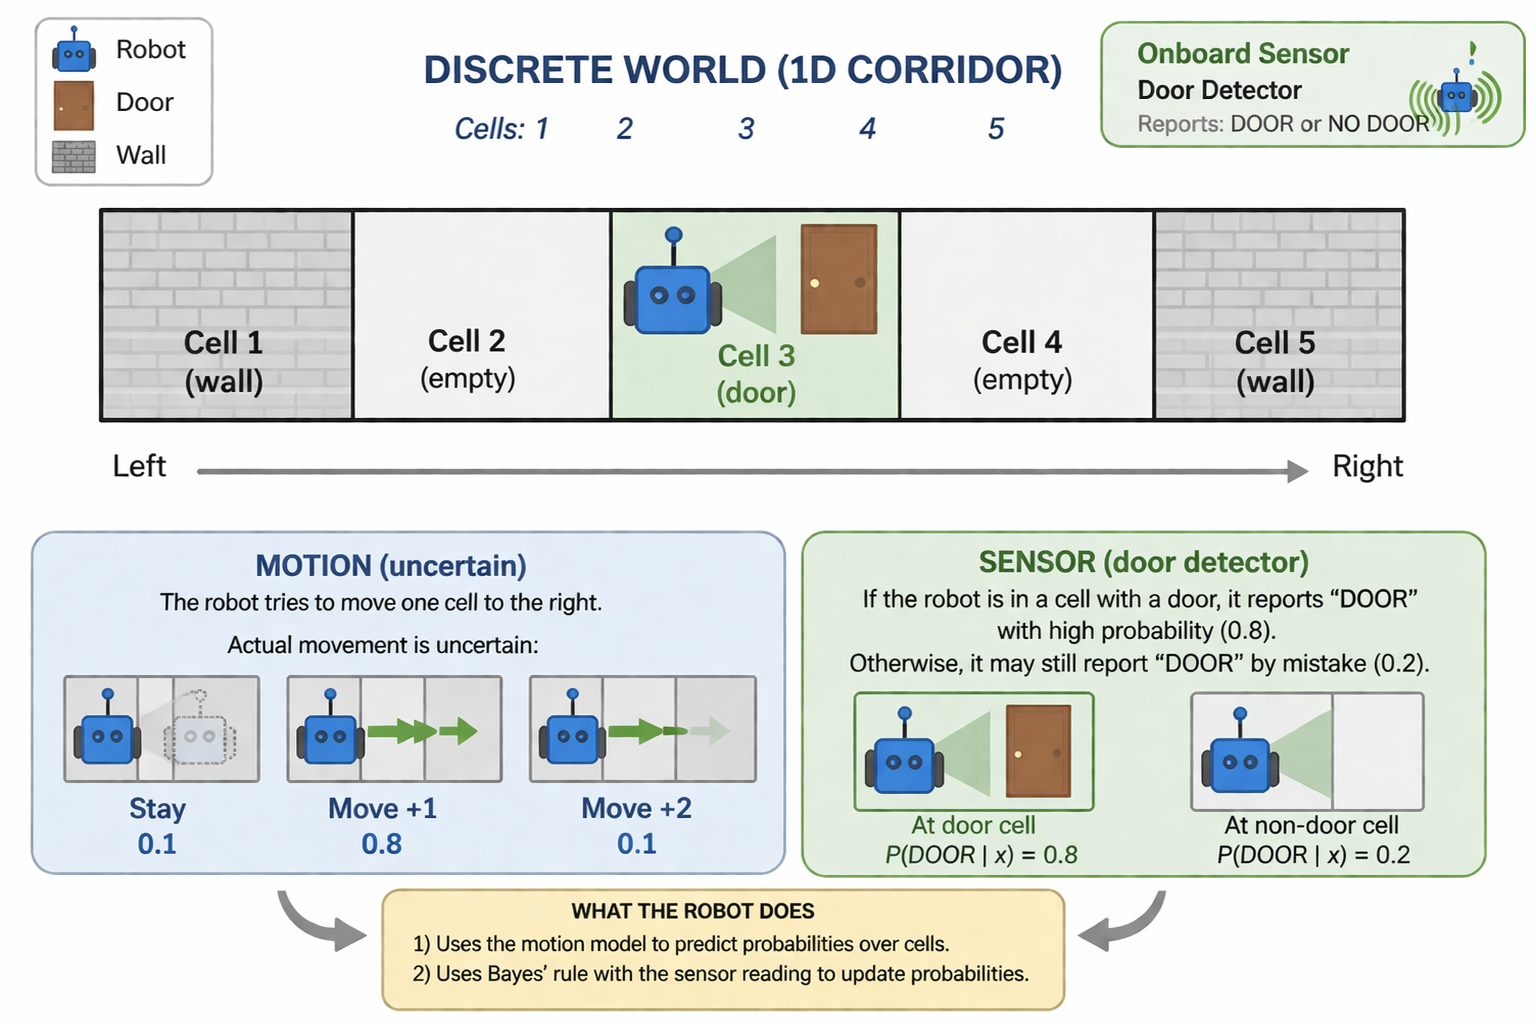

Let us assume the following probabilities

clear; clc; close all;

% Possible positions
cells = 1:5;

% Initial probabilities p(x)
p_x = [0.10 0.20 0.40 0.20 0.10];

disp('Initial probabilities p(x):');

Initial probabilities p(x):


disp(p_x);

    0.1000    0.2000    0.4000    0.2000    0.1000




fprintf('Sum = %.2f\n', sum(p_x));

Sum = 1.00


**Think**

- What does it mean that position 3 has probability 0.40? 

- Why must all probabilities sum to 1?

Visualizing the probabilities

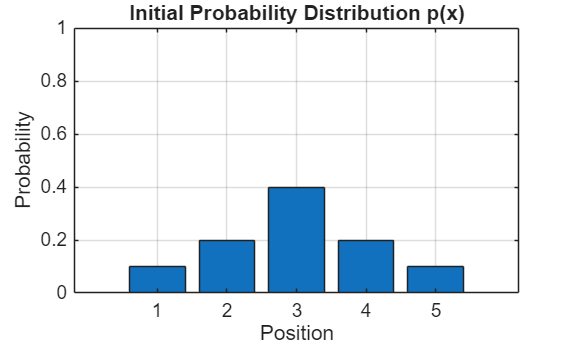

figure;
bar(cells, p_x);
ylim([0 1]);
grid on;
xlabel('Position');
ylabel('Probability');
title('Initial Probability Distribution p(x)');

Which position is most likely?

**Measurement**

The robot has a sensor that detects whether there is a **door**. Say, the corridor has a door only at position 3:

% Map: 1 means door, 0 means no door
map = [0 0 1 0 0];

Now suppose that sensor reports:

z = 1;   % 1 = "door detected"

**Conditional Probability**

Define $P\left(z=\textrm{door}\;|\;x\right)$.

This means: If the robot is at position $x$, what is the probability that the sensor detects a door?

Assume:

- If there is actually a door → probability = 0.8 

- Otherwise → probability = 0.2

p_z_given_x = zeros(1, length(cells));

for i = 1:length(cells)
    if map(i) == 1
        p_z_given_x(i) = 0.8;
    else
        p_z_given_x(i) = 0.2;
    end
end

disp('Conditional probabilities p(z = door | x):');

Conditional probabilities p(z = door | x):


disp(p_z_given_x);

    0.2000    0.2000    0.8000    0.2000    0.2000



Why is the probability highest at position 3?

Why are the other values not zero?

**Visualize conditional probability**

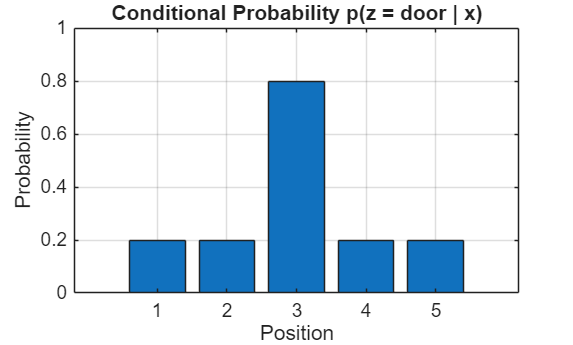

figure;
bar(cells, p_z_given_x);
ylim([0 1]);
grid on;
xlabel('Position');
ylabel('Probability');
title('Conditional Probability p(z = door | x)');

**Think**

What would this look like if the sensor were perfect?

**Total probability**

We now compute:$P\left(z=\textrm{door}\right)={\Sigma \;}_x P\left(z=\textrm{door}\;|\;x\right)\;P\left(x\right)$. This is called the **total probability.**

p_z = sum(p_z_given_x .* p_x);

fprintf('Total probability p(z = door) = %.4f\n', p_z);

Total probability p(z = door) = 0.4400


This value tells us: What is the overall probability of observing “door”, considering all possible positions?

**Question: **Why do we multiply and then sum?

**Bayes’ rule**

Now we want to compute: $P\left(x\;|\;z\right)$.

This means: What is the probability of position $x$, given that we observed “door”?

Apply Bayes' rule: $P\left(x\;|\;z\right)=\frac{P\left(z|x\right)P\left(x\right)}{P\left(z\right)}$

% Numerator
p_x_given_z_unnorm = p_z_given_x .* p_x;

% Normalize
p_x_given_z = p_x_given_z_unnorm / sum(p_x_given_z_unnorm);

disp('Updated probabilities p(x | z = door):');

Updated probabilities p(x | z = door):


disp(p_x_given_z);

    0.0455    0.0909    0.7273    0.0909    0.0455




fprintf('Sum = %.2f\n', sum(p_x_given_z));

Sum = 1.00


**Compare before and after**

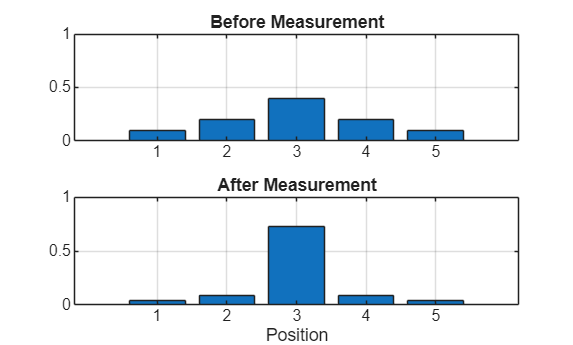

figure;

subplot(2,1,1);
bar(cells, p_x);
ylim([0 1]);
grid on;
title('Before Measurement');

subplot(2,1,2);
bar(cells, p_x_given_z);
ylim([0 1]);
grid on;
title('After Measurement');
xlabel('Position');

Which position becomes most likely after observing “door”?

Why does the probability at position 3 increase?

Why do other positions still have nonzero probability?

**Adding motion**

Now suppose the robot attempts to move **one step to the right**.

But motion is uncertain:

- 0.1 → stays in same position 

- 0.8 → moves one step right 

- 0.1 → moves two steps right 

**Motion update using total probability**

We compute: $P\left(x_k \right)={\Sigma \;}_{x_{k-1\;} } P\left(x_k \;|\;x_{k-1} \right)P\left(x_{k-1} \right)$

p_x_old = [0.10 0.20 0.40 0.20 0.10];

p_x_new = zeros(size(p_x_old));

for i = 1:length(cells)
    p_here = p_x_old(i);

    % stay
    j = i;
    p_x_new(j) = p_x_new(j) + 0.1 * p_here;

    % move one step right
    j = min(i+1, length(cells));
    p_x_new(j) = p_x_new(j) + 0.8 * p_here;

    % move two steps right
    j = min(i+2, length(cells));
    p_x_new(j) = p_x_new(j) + 0.1 * p_here;
end

disp('Probabilities after motion:');

Probabilities after motion:


disp(p_x_new);

    0.0100    0.1000    0.2100    0.3600    0.3200



Did the probabilities shift toward the right?

Why did the distribution spread out?

**Visualize the Motion Effect**

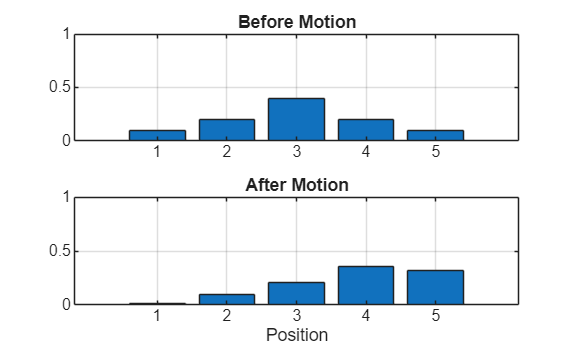

figure;

subplot(2,1,1);
bar(cells, p_x_old);
ylim([0 1]);
grid on;
title('Before Motion');

subplot(2,1,2);
bar(cells, p_x_new);
ylim([0 1]);
grid on;
title('After Motion');
xlabel('Position');

**Measurement after motion**

Now apply Bayes’ rule again:

% Reuse sensor model
p_z_given_x = zeros(size(cells));

for i = 1:length(cells)
    if map(i) == 1
        p_z_given_x(i) = 0.8;
    else
        p_z_given_x(i) = 0.2;
    end
end

% Update
p_x_post_unnorm = p_z_given_x .* p_x_new;
p_x_post = p_x_post_unnorm / sum(p_x_post_unnorm);

disp('Probabilities after motion + measurement:');

Probabilities after motion + measurement:


disp(p_x_post);

    0.0061    0.0613    0.5153    0.2209    0.1963



After motion and measurement, which position is most likely?

How does the measurement correct the uncertainty introduced by motion?

**Visualize Everything Together**

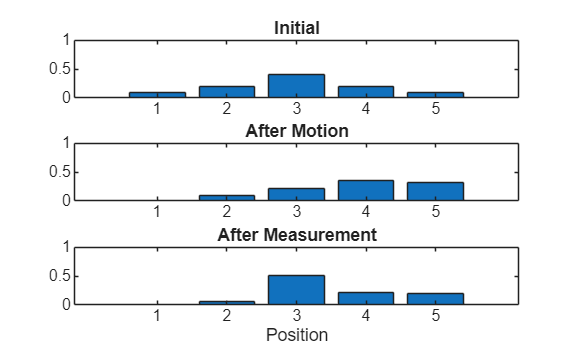

figure;

subplot(3,1,1);
bar(cells, p_x_old);
ylim([0 1]);
title('Initial');

subplot(3,1,2);
bar(cells, p_x_new);
ylim([0 1]);
title('After Motion');

subplot(3,1,3);
bar(cells, p_x_post);
ylim([0 1]);
title('After Measurement');
xlabel('Position');

**Prior and Posterior Probabilities: **The prior probability $
p(x)$ represents knowledge about a variable before incorporating new data. The posterior probability $p(x|y)$ represents the updated belief after observing data $y$. In mobile robotics, the prior may represent the robot’s position before sensor readings, and the posterior represents the corrected position after processing those readings. Bayesian inference thus provides a formal framework for updating beliefs, enabling a robot to fuse motion and perception data in a consistent probabilistic manner. 

**Summary: From Basic Probability to Localization**

**Prior (initial probability)**

- The starting probabilities over positions (`p_x`) 

- Represents what we believe *before* using the new measurement 

**Likelihood (conditional probability)**

- The sensor model (`p_z_given_x`) 

- Tells how likely the measurement is at each position 

- Measures consistency between position and observation 

**Total probability (normalization)**

- Computed as `p_z`

- Ensures all updated probabilities sum to 1 

- Combines prior and likelihood across all positions 

**Posterior (updated probability)**

- The updated probabilities (`p_x_given_z`) 

- Represents what we believe *after* using the measurement

**Key relationship**

- **Posterior ∝ Likelihood × Prior**

- Normalize to ensure probabilities sum to 1

**Effect of measurement**

- Positions consistent with the sensor → probability increases 

- Inconsistent positions → probability decreases 

- Uncertainty is reduced, but not eliminated (sensor is imperfect)

**Motion update (prediction step)**

- Redistributes probabilities (`p_x_new`) 

- Shifts probability in direction of motion 

- Spreads probability due to motion uncertainty

**Full cycle (intuitive)**

- Start with **Prior**

- Apply **Motion → Prediction**

- Apply **Measurement → Posterior**

## **Localization Problem**

The simple corridor example can now be generalized using the language of **belief-based localization**. Instead of treating the probabilities over positions as isolated calculations, we interpret them collectively as the robot’s **belief** about where it is. In this view, the initial probability distribution becomes the **prior belief**, the motion step produces a **predicted belief**, and the measurement update yields the **posterior belief**. This shift in terminology is useful because it extends naturally from a small discrete corridor to much broader localization problems involving larger maps, richer sensors, and repeated motion-measurement cycles.

One key terminology used above is that of belief. Belief representation methods are generally categorized into **single-hypothesis** and **multiple-hypothesis** systems.

**Single-Hypothesis Belief**

A single-hypothesis belief assumes that the robot’s position is known as a unique point in the environment. This may be expressed:

- As a coordinate in a continuous geometric map,

- As a discrete cell in a grid map, or

- As a node in a topological graph.

This representation is simple and computationally efficient. It allows clear, unambiguous decision-making and straightforward position updates.

However, in practice, sensor and effector noise introduce uncertainty, making it difficult or impossible to maintain a single definitive position estimate. As uncertainty increases, single-hypothesis systems risk losing localization accuracy. 

**Multiple-Hypothesis Belief**

Multiple-hypothesis representations maintain several possible positions simultaneously, along with measures of their likelihood. The robot’s belief can be expressed as:

- A geometric region (e.g., polygonal area of possible poses),

- A probability distribution (e.g., Gaussian belief, as in Kalman filters), or

- A set of discrete positions with associated probabilities (as in Markov or particle filters).

This representation explicitly models uncertainty and allows the robot to reason about ambiguity. It also supports active localization, where the robot selects actions that reduce uncertainty (e.g., moving toward informative landmarks).

The drawbacks are primarily computational. Representing and updating many hypotheses can be expensive, especially in large or high-dimensional environments. Practical systems therefore use simplified forms, such as Gaussian, multi-Gaussian, or hybrid metric-topological models to balance accuracy and efficiency.

Multiple-hypothesis position representations are advantageous because they allow a robot to explicitly maintain and update its belief about possible positions within the environment. Ideally, the robot’s belief state evolves consistently with both its motor commands and sensory observations. A simple geometric approach to multiple-hypothesis representation defines a set of possible robot positions as a polygon within the map. However, this method lacks any measure of how likely each position is relative to the others. **Probabilistic localization** extends this concept by associating explicit **probabilities** with each possible robot pose. The motivation for such approaches arises from the fact that sensor data are inherently noisy, and actuator commands are imperfect. Consequently, the robot’s true position cannot be known exactly but can instead be described as a **probability distribution** over all possible poses. Two major classes of probabilistic map-based localization are widely used:

- **Markov localization**, which represents belief as a full probability distribution over discrete positions, and

- **Kalman filter localization**, which models belief as a Gaussian probability density centered around a single estimated pose.

#### **Markov Localization**

Let $t$ denote time and $x_t$ the robot’s state (position and orientation). For planar motion, $x_t=[x,y,\theta ]^T$ defines a three-dimensional state vector. The full path of the robot is represented as $X_t=\{x_0,x_1,x_2,\ldots,x_t\}$. The control input or proprioceptive data at time $t,$ denoted $u_t,$ corresponds to information such as wheel encoder readings, IMU data, or motor commands. The sequence of control inputs up to time $t$ is $U_t=\{u_0,u_1,u_2,\ldots,u_t\}$. In the absence of noise, all past poses could be recovered by integrating $U_t$ from a known initial position. However, noise in proprioceptive sensors causes drift, which must be corrected using external observations. Exteroceptive sensors such as cameras, laser rangefinders, or sonars provide information about the environment. Their outputs (distances, angles, or feature coordinates) are called observations or measurements, denoted by $z
_t
	

.$ The sequence of measurements is $Z_t=\{z_0,z_1,z_2,\ldots,z_t \}$. Furthermore, let $M$denote the true, static map of the environment, consisting of $n$ landmarks. The vector vector representing the coordinates of the landmark is given by $M=\{m_0,m_1,\ldots,m_{n-1}\}$, where $m_i$ represents the position (and possibly orientation) of a feature in world coordinates. The map remains constant over time.

This broader framework is known as **Markov localization**. Its central idea is that the robot maintains a probability distribution over all possible states and updates it recursively as new actions and observations arrive. The word *Markov* reflects the assumption that the current state contains all the information needed for the next update: the future depends only on the present state, not on the full past history.

As the robot cannot directly measure its true pose, it maintains a probabilistic estimate of its state given past data. This belief is expressed as a conditional probability distribution: $bel(x_t)=p(x_t|Z_t,U_t,M)$ representing the probability that the robot is at pose $x_t$ given all past observations $Z_t$ and control inputs $U_t$. The prediction update occurs immediately after receiving the control input $u_t$ but before the new observation $z_t$, which is given by $bel(x_t)=p(x_t|Z_{t-1},U_t,M)$. This step estimates the robot’s belief purely based on motion information and typically increases uncertainty. The correction (measurement) update incorporates the new observation $z
_t
	

,$ refining the belief: $bel(x_t)=p(x_t|Z_t,U_t,M)$. This step reduces uncertainty and aligns the belief with sensor data. 

To perform probabilistic localization, several components are required:

**Initial belief **$bel(x_0)$: represents the robot’s initial position knowledge.

- If the initial location is unknown, $bel(x_0)$ is uniform over all poses.

- If known precisely, it is a Dirac delta function centered at the true position.

**Map **$M$: a known environmental representation. If unavailable, the robot must build it simultaneously (the SLAM problem).

**Sensor data: ** consisting of proprioceptive inputs $u_t$ and exteroceptive measurements $z_t$. 

**Probabilistic motion model:** derived from the robot’s kinematics given by $x_t=f(x_t-1,u_t)$ incorporating noise terms to model motion uncertainty: $p(x_t | u_t, x_{t-1}) = \mathcal{N}(f(x_{t-1}, u_t), Q_t)$ where $Q_t$ is the motion noise covariance.

**Probabilistic measurement model:** defines the likelihood of an observation given the robot’s pose and the map. mathematically it is expressed as $p(z_t | x_t, M) = \mathcal{N}(h(x_t, M), R_t)$. Here, $h(x_t, M)$ is the expected, noise-free measurement derived from the map, and $R_t$ is the sensor noise covariance.

**Algorithm**

Markov localization is a probabilistic method that represents the robot’s belief over its pose as an arbitrary probability distribution over the state space and updates that belief by alternating prediction (action) and measurement (perception) steps. In practice this is most often implemented on a discretized state space (grid or topological nodes), so the belief is a table of probabilities over cells or nodes.

Let $x_t
$ be the robot state at time $t,u_{t\;}$the control (proprioceptive) input at time $t$ and $z_t $ the exteroceptive observation at time $t\ldotp$ The robot maintains a belief $bel(x_t)=p(x_t|Z_t,U_t,M)$, where $Z_t=\{z_0,\ldots,z_t\}, U_t=\{u_0,\dots,u_t\}$and $M$ is the known map. Two core probabilistic ingredients are required: 

- **Motion model **$p(x_t \mid u_t, x_{t-1})$ — probability of transitioning to $x_t$ given previous state $x_{t-1}$ and control $u_t.$ This captures odometry uncertainty.

- **Measurement model **$p(z_t \mid x_t, M)$ — likelihood of observing $z_t$ if the robot were in pose $x_t$ given the map $M$.

Using the total probability theorem (prediction) and Bayes’ rule (measurement), the recursive update is given by $\bar{bel}(x_t)=\int p(x_t|u_t,x_{t-1})bel(x_{t-1})dx_{t-1}$ or discrete sum over $
x_{t-1}$ when state space is discretized. Furthermore the measurement (correction) update is given by $bel(x_t)=\eta p(z_t|x_t,M)\bar {bel}(x_t),$ where $\eta $ normalizes the distribution. These two equations form the Bayes filter specialized to Markov localization.

**Key intuition**

Markov localization provides a general recipe:

- **Prior belief** captures current uncertainty 

- **Motion model** predicts how uncertainty evolves 

- **Sensor model** corrects that uncertainty using observations 

- **Posterior belief** becomes the robot’s updated state estimate 

So the corridor example is not just a toy calculation. It is the simplest instance of a general probabilistic algorithm that scales to real robotic systems operating under uncertainty

### **Learning by Doing Exercise**

Consider a robot moving along a corridor with **10 discrete positions**.

The robot does not know its exact position. Instead, it maintains a probability distribution over all possible positions. In Markov localization, this probability distribution is called the **belief**.

- **State**: robot position 

- **Belief**: probability assigned to each possible position 

- **Goal**: update this belief as the robot senses and moves

**Initialize the world**

clear; clc; close all;

% Number of possible positions
num_positions = 10;

% Initial belief: all positions equally likely
initial_belief = ones(1, num_positions) / num_positions;

% Sensor accuracy
sensor_accuracy = 0.6;

% Motion accuracy
motion_accuracy = 0.8;

% Assumed true position of the robot
true_position = 3;

**Think**

- What does `num_positions = 10` represent? 

- Why does a uniform initial distribution mean maximum uncertainty? 

- If the robot knew exactly where it was at the start, what would the initial belief look like?

**Prior belief**

The **prior belief** is the probability distribution before incorporating new information at a given step.

Here, the initial prior is uniform:

initial_belief

initial_belief =     0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000


This means the robot initially considers all positions equally likely

**Visualize the initial prior**

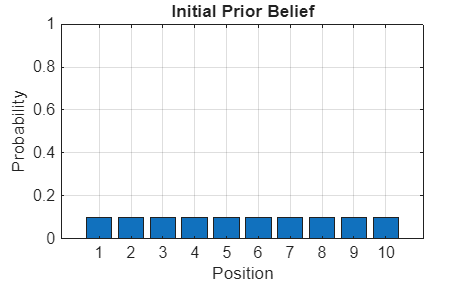

figure;
bar(initial_belief);
ylim([0 1]);
title('Initial Prior Belief');
xlabel('Position');
ylabel('Probability');
grid on;

**Question**: Which position is most likely initially?

**Question: **Why is this called a **prior**?

**Sensor Model**

The **sensor model** tells us how likely a measurement is for each possible state.

In this example, the robot is assumed to be near position 3, and the sensor is most likely to respond correctly there. Neighboring positions also get some probability.

This corresponds to:

- high probability at the true position 

- lower probability at nearby positions 

- zero elsewhere

% Sensor model: P(measurement | position)
sensor_model = zeros(1, num_positions);
sensor_model(true_position) = sensor_accuracy;
sensor_model(true_position-1) = (1-sensor_accuracy)/2;
sensor_model(true_position+1) = (1-sensor_accuracy)/2;

% Normalize
sensor_model = sensor_model / sum(sensor_model);

disp('Sensor model:');

Sensor model:


disp(sensor_model);

         0    0.2000    0.6000    0.2000         0         0         0         0         0         0



**Plot Sensor Model**

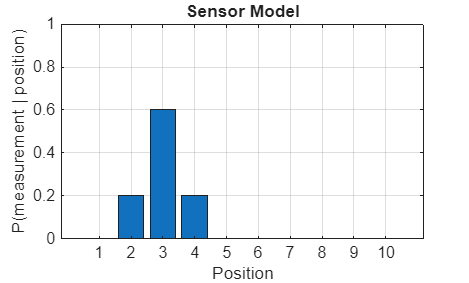

figure;
bar(sensor_model);
ylim([0 1]);
title('Sensor Model');
xlabel('Position');
ylabel('P(measurement | position)');
grid on;

- **Sensor model / measurement model**: tells how likely the observation is at each possible state 

- **Likelihood**: the same idea viewed as a function over states for a given measurement 

So in this activity:

- `sensor_model` acts as the **likelihood**

**Question: **Why is the highest sensor probability at position 3?

**Question: **Why do positions 2 and 4 also have nonzero probability?

**Motion Model**

The **motion model** tells us how probability moves from one state to another after an action.

Here, motion is uncertain:

- with probability `motion_accuracy`, the robot moves as intended 

- with the remaining probability, it may stay behind

% Motion model: P(new position | old position)
motion_model = diag(ones(1, num_positions)) * motion_accuracy + ...
               diag(ones(1, num_positions - 1), 1) * (1 - motion_accuracy);

% Last position remains last
motion_model(end, end) = 1;

disp('Motion model:');

Motion model:


disp(motion_model);

    0.8000    0.2000         0         0         0         0         0         0         0         0
         0    0.8000    0.2000         0         0         0         0         0         0         0
         0         0    0.8000    0.2000         0         0         0         0         0         0
         0         0         0    0.8000    0.2000         0         0         0         0         0
         0         0         0         0    0.8000    0.2000         0         0         0         0
         0         0         0         0         0    0.8000    0.2000         0         0         0
         0         0         0         0         0         0    0.8000    0.2000         0         0
         0         0         0         0         0         0         0    0.8000    0.2000         0
         0         0         0         0         0         0         0         0    0.8000    0.2000
         0         0         0         0         0         0         0         0         0 

- **Motion model / state transition model**: tells how the robot may move from one state to another 

- **Prediction step**: uses the motion model to propagate the current belief forward

**Visualize Motion Model**

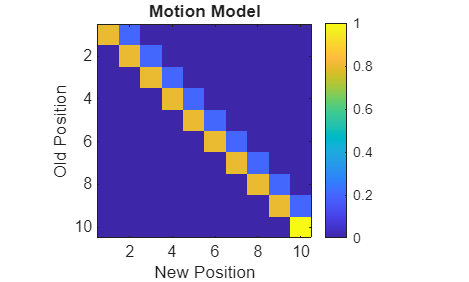

figure;
imagesc(motion_model);
colorbar;
title('Motion Model');
xlabel('New Position');
ylabel('Old Position');
axis equal tight;

**Question: **What does a strong diagonal in the motion model indicate?

**Question: **Why is the motion model a matrix?

**Markov localization cycle**

Markov localization repeats two main steps:

**Update step**

Use the current measurement to reweight the probabilities.

**Prediction step**

Use the motion model to shift/spread the probabilities after movement.

The result of one cycle becomes the input for the next cycle.

Before running the full algorithm, let us organize the key terms:

- **State**: one possible robot position 

- **Belief**: probability distribution over states 

- **Prior**: belief before current measurement update 

- **Likelihood**: sensor-based weighting of states 

- **Posterior**: updated belief after using the measurement 

- **Prediction**: belief after applying the motion model 

- **Recursive estimation**: repeating this process over time

Below is a running version of the algorithm with plots after every step.

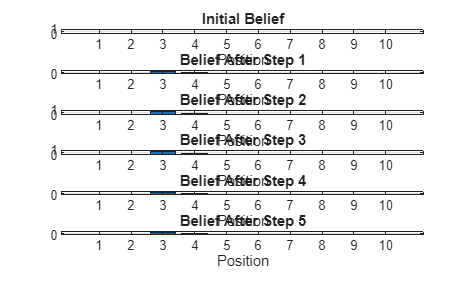

beliefs = initial_belief;
num_steps = 5;

figure;

subplot(num_steps+1, 1, 1);
bar(beliefs);
ylim([0 1]);
title('Initial Belief');
xlabel('Position');
ylabel('Belief');
grid on;

for step = 1:num_steps
    
    % -----------------------------
    % Measurement update
    % -----------------------------
    prior_belief = beliefs;
    
    likelihood = sensor_model;
    
    posterior_unnormalized = likelihood .* prior_belief;
    posterior_belief = posterior_unnormalized / sum(posterior_unnormalized);
    
    % -----------------------------
    % Prediction step
    % -----------------------------
    predicted_belief = posterior_belief * motion_model;
    
    % Store updated belief for next iteration
    beliefs = predicted_belief;
    
    % -----------------------------
    % Plot
    % -----------------------------
    subplot(num_steps+1, 1, step+1);
    bar(beliefs);
    ylim([0 1]);
    title(['Belief After Step ' num2str(step)]);
    xlabel('Position');
    ylabel('Belief');
    grid on;
end

At each step:

**Prior**

`prior_belief = beliefs`

This is the current probability distribution before using the new sensor information.

**Likelihood**

`likelihood = sensor_model`

This tells how compatible each position is with the current measurement.

**Posterior**

`posterior_belief = ...`

This is the updated probability distribution after applying the measurement.

**Prediction**

`predicted_belief = posterior_belief * motion_model`

This redistributes probability according to possible motion outcomes.

**Question: **Why does the belief become concentrated near certain positions after repeated updates?**Question: **Why does motion spread the belief slightly even when the sensor keeps reinforcing one area?

Let us run just one step and display all intermediate quantities.

beliefs = initial_belief;

prior_belief = beliefs

prior_belief =     0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000


likelihood = sensor_model

likelihood =          0    0.2000    0.6000    0.2000         0         0         0         0         0         0



posterior_unnormalized = likelihood .* prior_belief

posterior_unnormalized =          0    0.0200    0.0600    0.0200         0         0         0         0         0         0


posterior_belief = posterior_unnormalized / sum(posterior_unnormalized)

posterior_belief =          0    0.2000    0.6000    0.2000         0         0         0         0         0         0



predicted_belief = posterior_belief * motion_model

predicted_belief =          0    0.1600    0.5200    0.2800    0.0400         0         0         0         0         0


**Question: **Which positions gained probability? 

**Question: **Which positions lost probability? 

**Question: **Compare `posterior_belief` and `predicted_belief`.

- Which way did the probabilities shift? 

- Why?

**Reflection Questions**

- What is the difference between **belief** and **state**? 

- Why is the sensor model called a **likelihood**? 

- Why is normalization necessary after measurement update? 

- Why does motion usually increase uncertainty? 

- What is the difference between **posterior belief** and **predicted belief**? 

- Why is this called a **recursive** algorithm? 

- What does the word **Markov** mean in this context?

### Learning by Doing Exercise

This example shows how a robot estimates its position using **probabilistic localization**.

The key idea is simple:

The robot does not know its true position.

It maintains a **belief distribution** and keeps updating it using motion and sensor data.**⚙️ What the Code Does**

At each time step, the system performs three main operations:

** 1. True Robot Motion (Ground Truth)**

- The robot moves forward by a command `u`

- Noise is added to simulate real-world uncertainty 

- A sensor provides a **noisy measurement** of position 

`x_true = x_true + u + noise`

`z = x_true + measurement_noise`

 This represents the **real world**, which the robot does not directly know.

**2. Prediction Step (Motion Update)**

- The belief is **shifted** according to motion 

- It is then **spread out** to account for uncertainty 

**3. Measurement Update (Correction)**

- A probability distribution is created around the sensor reading 

- The belief is updated by combining: 

- prediction 

- measurement 

`posterior = prediction × measurement`

 This step **reduces uncertainty**.

**What to Observe****Early Steps**

- Belief has multiple peaks 

- Robot is uncertain about its position 

**Middle Steps**

- Measurement begins to correct belief 

- One hypothesis becomes stronger 

**Final Steps**

- Belief aligns with true position 

- Localization is achieved 

**What You Can Tune**

1. Motion (`u`**)**

- Controls how fast the robot moves 

- Larger motion → harder prediction 

**2. Motion Noise (**`motion_noise`**)**

- Controls uncertainty in movement 

- High → belief spreads 

- Low → belief stays sharp 

**3. Measurement Noise (**`meas_noise`**)**

- Controls trust in sensor 

- Low → strong correction 

- High → weak correction 

**4. Initial Belief**

- Single peak → robot is confident 

- Multiple peaks → ambiguity

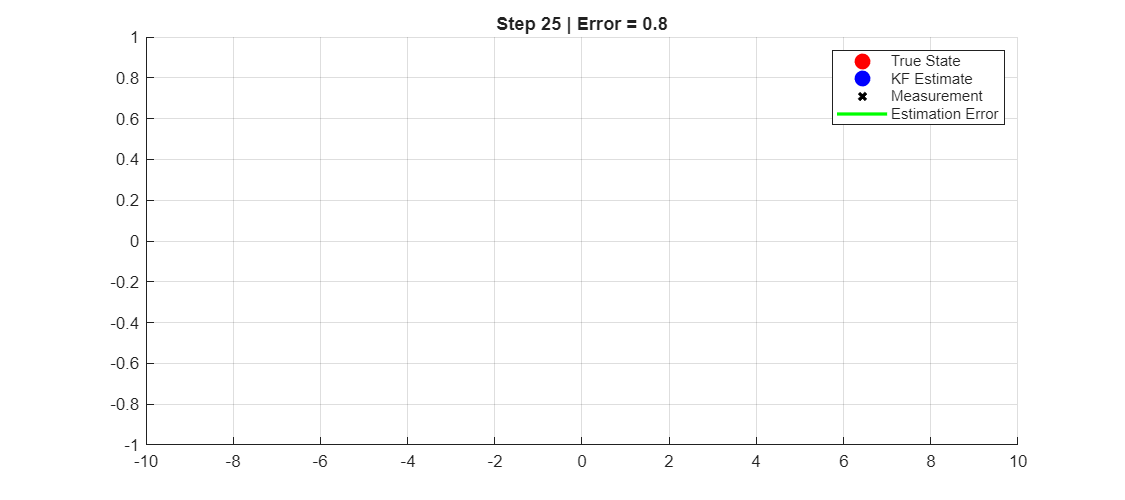

%% 📊 Task: Robot Motion + Belief Evolution

x = linspace(-10,10,200);

% ===== 🔧 INITIAL BELIEF (WHAT THE ROBOT THINKS INITIALLY) =====
% 👉 Change this to test:
% - single peak (certain start)
% - multiple peaks (ambiguous start)
belief = exp(-(x+4).^2/2) + exp(-(x-4).^2/2);
belief = belief / max(belief);

% ===== 🔴 TRUE ROBOT STATE (GROUND TRUTH - NOT KNOWN TO ROBOT) =====
x_true = -4;

% ===== 🔧 PARAMETERS TO TUNE =====

u = 0.5;  
% 👉 Motion command (how much robot moves each step)
% Try: 0.2 (slow), 1.0 (fast)

motion_noise = 0.5;  
% 👉 Process noise (uncertainty in motion)
% High → belief spreads more
% Low → belief stays sharp

meas_noise = 1.0;    
% 👉 Sensor noise (measurement reliability)
% Low → strong correction
% High → weak correction

figure

for k = 1:15
    
    clf
    
    %% ===== 🔴 TRUE ROBOT MOTION =====
    % (Robot moves with noise — real world is imperfect)
    x_true = x_true + u + 0.1*randn;
    
    % Sensor reading (noisy measurement of position)
    z = x_true + meas_noise*randn;
    
    %% ===== 🔵 PREDICTION STEP =====
    % Shift belief based on motion
    pred = interp1(x, belief, x-u, 'linear', 0);
    
    % Add uncertainty (spread the belief)
    kernel = exp(-(x).^2/(2*motion_noise^2));
    pred = conv(pred, kernel, 'same');
    pred = pred / max(pred);
    
    %% ===== 🟢 MEASUREMENT UPDATE =====
    % Create measurement likelihood
    meas = exp(-(x-z).^2/(2*meas_noise^2));
    
    % Combine prediction and measurement (Bayes update)
    post = pred .* meas;
    post = post / max(post);
    
    % Update belief
    belief = post;
    
    %% ===== 🔴 PLOT TRUE ROBOT =====
    subplot(2,1,1)
    plot(x_true,0,'ro','MarkerSize',10,'MarkerFaceColor','r'); hold on
    xlim([-10 10]); ylim([-1 1])
    title(['True Position = ',num2str(x_true,2)])
    grid on
    

    %% ===== 🔵 PLOT BELIEF =====
    subplot(2,1,2)
    plot(x, belief,'LineWidth',2); hold on
    
    % Measurement (normalized for visualization)
    plot(x, meas/max(meas),'--')
    
    % True position reference
    xline(x_true,'r','LineWidth',2)
    
    legend('Belief','Measurement','True Position')
    title('Belief Distribution')
    grid on
    
    pause(0.6)
end

### Kalman Localization

Kalman-filter localization treats localization as a sensor-fusion problem under Gaussian uncertainty. The robot pose is modeled as a Gaussian distribution $\mathcal{N}(\mu_t, P_t)$, where $\mu_t$ is the mean state and $P_t$ its covariance. The Kalman filter is exact for linear systems with additive white Gaussian noise; for typical nonlinear mobile-robot motion and observation models we use the Extended Kalman Filter (EKF) which linearizes the models about the current estimate.

KF / EKF localization performs two alternating steps:

- Prediction (motion) update: propagate state mean and covariance through the motion model and increase uncertainty according to motion noise.

- Measurement (correction) update: incorporate sensor observations (features, ranges) to reduce uncertainty using the measurement model and its noise.

Kalman filter (KF) localization is a specialized form of Markov localization in which all probability density functions, motion model, and measurement model are approximated by Gaussian distributions. A Gaussian is fully described by its mean $\mu_t$ and covariance $\Sigma_t$, so the filter only needs to update these two parameters during prediction and correction. This makes KF localization far more efficient than a full Markov localization algorithm.

A major limitation arises from this assumption: the initial belief must also be Gaussian, meaning the robot must know its starting position with bounded uncertainty. As a consequence, the Kalman filter can track position but cannot globally localize from an unknown position, nor can it recover from the kidnapped robot scenario. 

#### Introduction to Kalman Filter Theory

Tthe Kalman filter relies on two fundamental assumptions:

- The system dynamics and measurement models are linear, and

- All noise sources (robot motion noise, odometric error, and sensor measurement noise) are white Gaussian.

A Gaussian distribution is fully described by its first two moments: the mean $\mu$ and variance $\sigma^2$. When the robot’s configuration is represented by a vector, the belief becomes a multivariate Gaussian, described by a mean vector $\mu_t$ and covariance matrix $\Sigma_t$. During Kalman filtering, only these two quantities are updated. Thus, the complete Kalman filter is built from four equations:

- Two for the prediction update (mean and covariance)

- Two for the measurement update (mean and covariance)

Just as in Markov localization, the Kalman filter prediction step arises from the theorem of total probability, while the correction step arises from Bayes’ rule.

**Prediction Step: **Let $x_1$ and $x_2
$ be two independent Gaussian random variables given by $x_1=\mathcal{N}(\mu _1,\sigma _1^2)$ and $x_2=\mathcal{N}(\mu _2,\sigma _2^2)$ respectively. Assume a new variable$y$ is obtained through a function of these two variables: $y=f(x_1,x_2)$.

If $f$ is linear, $y=Ax_1+Bx_2$ and $x_1,x_2$ are independent Gaussians, then $y$ is also Gaussian, with $E(y)=A\mu _1+B\mu _2$ and $\sigma _y^2=A^2\sigma _1^2+B^2\sigma _2^2$ . For vector variables with covariances $\Sigma 
_1
	

,\Sigma 
_2
	

:$ $E(y)=A\mu _1+B\mu _2$ and $\Sigma _y=A\Sigma _1A^T+B\Sigma _2B^T$.

If $f$ is non-linear, then $y$ is not Gaussian. However, the first-order Taylor expansion of $f$ around $(\mu_1, \mu_2)$ gives: $y\approx f(\mu _1,\mu _2)+F_1(x_1-\mu _1)+F_2(x_2-\mu _2)$, where $F_{1\;}$and $F_2$ are the Jacobians of $f$. Therefore, $E(y)=f(\mu _1,\mu _2)$ and $\Sigma _y=F_1\Sigma _1F_1^T+F_2\Sigma _2F_2^T$ . 

**Measurement Update: **Let $q$ is the robot position, $p_1(q)$ is the belief after prediction update and $p_2(q)$ is the measurement likelihood from an exteroceptive sensor. Both $p_1(q)$ and $p_2(q)$ are Gaussian and is denoted by $p_1(q)=\mathcal{N}(q,\sigma _1^2)$ and $p_2(q)=\mathcal{N}(q,\sigma _2^2)$ respectively. Bayes rule states that $p(q)\propto p_1(q)p_2(q)$. This leads to the equation $\frac{1}{\sqrt{2 \pi \sigma _1}}exp(-\frac{(q-\mu_1)^2}{2 \sigma _1 ^2}) \dot{} \frac{1}{\sqrt{2 \pi \sigma _2}}exp(-\frac{(q-\mu_2)^2}{2 \sigma _2 ^2})$ . Rearranging the exponent yields a Gaussian of the form $p(q) = C exp(-\frac{(q-\mu_1)^2}{2 \sigma  ^2})$.  We obtain $\mu =\frac{\sigma _2^2\mu _1+\sigma _1^2\mu _2}{\sigma _1^2+\sigma _2^2}$ , $\sigma ^2 =\frac{\sigma _1^2\sigma _2^2}{\sigma _1^2+\sigma _2^2}$ after carrying out the algebra. Equivalently, $\mu =\mu _1+\frac{\sigma _1^2}{\sigma _1^2+\sigma _2^2}(\mu _2-\mu _1)$ and $\sigma ^2 =\sigma _1^2 -\frac{\sigma _1^4}{\sigma _1^2+\sigma _2^2}$. The fraction $\frac{\sigma _1^2}{\sigma _1^2+\sigma _2^2}$ is the Kalman gain in 1D.

For $n$-dimensional vectors, the fused mean and covariance are: $\mu =\mu _1+P(P+R)^{-1}(\mu _2-\mu _1)$ and $\Sigma =P-P(P+R)^{-1}P$. This is typically written in standard Kalman filter notation as $\mu =\mu _1+K(\mu _2-\mu _1)$ and $\Sigma =(I-K)P$ where $K=P(P+R)^{-1}$ is the Kalman gain. 

#### Localization Algorithm

The overall flow is given below:

- **Prediction update** using odometry + motion model

- **Observation step** (extract sensor features)

- **Measurement prediction** (predict what features should be visible)

- **Matching step** (pair observed features with expected ones)

- **Estimation step** using Kalman equations

**Prediction Update – Using the Theorem of Total Probability: **The robot’s predicted state $x_t$ at time $t$ depends on the previous state $x
_{t-1}
	
$ and the control input $u_t$: $x_t=f(x_{t-1},u_t)$. For a differential-drive robot, $f$ is the odometric motion model. Given the system model and noise, the associated covariance is computed using the linearized error propagation law: $P_t=F_tP_{t-1}F_t^T+Q_t$, where $F_{t\;}$s the Jacobian of the motion model $f$ w.r.t. state, $Q_t$ is the covariance of the control/motion noise $P_{t-1}$ is the previous state covariance.

**Measurement Update – Using the Bayes' Rule: **

Let $q$ denote the robot position, $p_1(q) $ be the robot’s belief after the prediction update, and $p_2(q)$ be the belief based on the exteroceptive sensor measurement. In Kalman filtering, all probability densities are assumed to be Gaussian: $p_1(q)= \mathcal{N}(\mu 1,\sigma _2^2)$ and $p_2(q)= \mathcal{N}(\mu _2,\sigma _2^2)$. According to Bayes rule, the posterior distribution after receiving the measurement is $p(q)\propto p_1(q)p_2(q)$, which is equivalent to $p(q)\propto\frac{1}{2\pi\sigma_1\sigma_2}exp \pmatrix{-\frac{(q-\mu _1)^2}{2\sigma _1^2}-\frac{(q-\mu _2)^2}{2\sigma _2^2}}$ , note that the exponent is** quadratic** in $q$, so the result is another Gaussian. We rewrite the exponent as $-\frac{(q-\mu _1)^2}{2\sigma _1^2}-\frac{(q-\mu _2)^2}{2\sigma _2^2} = \frac{(q-\mu )^2}{2\sigma^2}+C$, where $C$ is a constant that normalizes the distribution.

Solving for the new mean $\mu$ and variance $\sigma^2$, we get 

$\mu = \frac{\sigma _2^2\mu _1+\sigma _1^2\mu _2}{\sigma _1^2+\sigma _2^2}$ ; or $\mu = \mu_1+\frac{\sigma _1^2}{\sigma _1^2+\sigma _2^2}(\mu_2-\mu_1)$

$\sigma ^2 =\frac{\sigma _1^2 \sigma _2^2}{\sigma _1^2+\sigma _2^2}$; or $\sigma ^2 =\sigma _1 ^2 - \frac{\sigma _1^4}{\sigma _1^2+\sigma _2^2}$ . This shows $\sigma ^2<\sigma ^12, \; \sigma ^2<\sigma _2^2$ i.e., combining two uncertain estimates always decreases uncertainty.

For $n$-dimensional Gaussians, the prior and measurement (or posterior) mean and covariance is given by $\left(\mu_1 ,P\right)$ and $\left(\mu_2 ,R\right)$. Then the fused mean and covariance can be given by $\mu =\mu _1+P(P+R)^{-1}(\mu _2-\mu _1)$ and $\Sigma =P-P(P+R)^{-1}P$ respectively. We can now rewrite $K=P(P+R)^{-1}$, which is the kalman gain. Therefore the update equations becomes, $\mu =\mu _1+K(\mu _2-\mu _1)$ (State Update) and $\Sigma =(I-K)P$ (Covariance Update).

For localiztion of mobile robots using Kalman filter, the following steps are necessary:

- **Prediction update** using odometry and motion model.

- **Observation**: extract features from sensor data.

- **Measurement prediction**: compute what features should be visible.

- **Matching**: pair observed and predicted features.

- **Estimation**: fuse all matches using Kalman update equations.

**Prediction Update: T**he robot’s state at time $t$ is predicted using the motion model $x_t=f(x_{t-1},u_t)$, the covariance is propagated using the linearized error propagation law $P_t=F_tP_{t-1}F_t^T+Q_t$, where $F_t= \frac{\partial f}{\partial x}|_{x_{t-1}, u_t}$ is the Jacobian of the motion model, $Q_t$ is the motion noise covariance.

**Observation: **The robot receives sensor observation in the form of $z_t = \{\, z_t^{\,i} \mid i = 1,\dots,n \,\}$.

**Measurement Prediction: **Using the predicted pose $x_t$ and the map$M$, the robot generates predicted feature measurements given by $z_{t}^{\,j,p} = h(x_t, m_j)$, where $h\left(\cdot \right)$ transforms map feature $m_j$ into the sensor frame.

**Matching: **or each possible pairing of actual and predicted features, compute the **innovation**: $v_{ij} = z_t^{\,i} - h(x_t, m_j) $ and the innovation covariance is given by $S_{ij} = H_{j}\, P_t \, H_{j}^{T} + R_{i} $, where $H_j = \frac{\partial h}{\partial x}$ (Jacobian of the measurement model),  $R_i$ is the measurement noise covariance for $z
_t
^i
	
$. To check whether an observation matches a predicted feature, we use the Mahalanobis distance $d_{ij}^{2} = v_{ij}^{T} \, S_{ij}^{-1} \, v_{ij}$.

**Estimation: **Stack all validated measurements into the following :

- composite measurement vector $z_t$

- composite innovation vector $v_t$

- composite Jacobian $H$

- composite measurement noise matrix $R_t = \mathrm{diag}(R_i)$

- Compute the composite innovation covariance $S_t = H\, P_t\, H^{T} + R_t$

- Apply the Kalman update: $x_t = x_t + K_t\, v_t $ (state update), $P_t = P_t - K_t\, S_t\, K_t^T$ (Covariance Update), where $K_t = P_t\, H^{T}\, S_t^{-1} $ is the Kalman gain

**Interpretation: **New estimate=Prediction+Kalman-weighted innovation

#### Learning by Doing Exercise

This example shows how a robot estimates its position using a **Kalman Filter**.

Unlike earlier belief-based methods, the Kalman Filter does not store the full distribution. Instead, it tracks only:

- the **state estimate** 

- the **uncertainty** 

**What the Code Does**

At each time step, the system performs three key operations:

** 1. True System (Reality)**

- The robot moves forward by a command `u`

- Motion is affected by noise 

- A sensor provides a noisy measurement `z`

`x_true = x_true + u + noise`

`z = x_true + measurement_noise`

This represents the **real world**, which is not directly known to the filter.

**2. Prediction Step**

The filter predicts the next state based on motion:

- Estimate is shifted using motion 

- Uncertainty increases 

`x_pred = x_est + u`

`P_pred = P + Q`

This models:

- imperfect motion 

- uncertainty accumulation 

** 3. Update Step**

The filter corrects the prediction using the measurement:

- Compute Kalman Gain: 

`K = P_pred / (P_pred + R)`

- Update estimate: 

`x_est = x_pred + K*(z - x_pred)`

- Update uncertainty: 

`P = (1 - K)*P_pred`

👉 This step reduces error using sensor information.

** What to Observe****Early Steps**

- Estimate is far from true position 

- Measurements help guide correction 

**Middle Steps**

- Estimate starts tracking the true state 

- Error reduces 

**Final Steps**

- Estimate closely follows true position 

- Small fluctuations remain due to noise 

**What You Can Tune**

1. Process Noise (`Q`**)**

- Controls uncertainty in motion 

- High → less trust in prediction 

- Low → more trust in prediction 

**2. Measurement Noise (**`R`**)**

- Controls trust in sensor 

- Low → strong correction 

- High → weak correction 

**3. Motion (**`u`**)**

- Controls how fast the robot moves 

- Larger motion → harder tracking

com.mathworks.services.Prefs.setBooleanPref('LiveEditorFigureVisible', false);
clear; clc; close all;

%% 🤖 Task: Kalman Filter (KF) Localization

% ================== 🔧 PARAMETERS TO TUNE ==================
Q = 0.2;   
R = 0.5;   
u = 0.5;   
% ==========================================================

% ===== INITIAL STATE =====
x_est = 0;    
P = 1;        

x_true = -4;  

%% ✅ FORCE EXTERNAL WINDOW
f = figure('Name','Kalman Filter Localization', ...
           'WindowStyle','normal', ...
           'Position',[100 100 900 400], ...
           'Color','w');

set(f,'Visible','on');

ax = axes('Parent',f);
hold(ax,'on');
xlim(ax,[-10 10]); 
ylim(ax,[-1 1]);
grid(ax,'on');

%% Pre-create graphics (no clf → smoother)
h_true = plot(ax,nan,0,'ro','MarkerSize',10,'MarkerFaceColor','r');
h_est  = plot(ax,nan,0,'bo','MarkerSize',10,'MarkerFaceColor','b');
h_meas = plot(ax,nan,0,'kx','LineWidth',2);
h_err  = plot(ax,[nan nan],[0 0],'g','LineWidth',2);

legend(ax,'True State','KF Estimate','Measurement','Estimation Error');

for k = 1:25
    
    %% ===== 🔴 TRUE SYSTEM (REAL WORLD) =====
    x_true = x_true + u + sqrt(Q)*randn;
    
    z = x_true + sqrt(R)*randn;
    
    %% ===== 🔵 PREDICTION =====
    x_pred = x_est + u;     
    P_pred = P + Q;         
    
    %% ===== 🟢 UPDATE =====
    K = P_pred / (P_pred + R);
    
    x_est = x_pred + K*(z - x_pred);
    P = (1 - K)*P_pred;
    
    %% ===== 📊 VISUALIZATION (UPDATE ONLY) =====
    set(h_true,'XData',x_true);
    set(h_est,'XData',x_est);
    set(h_meas,'XData',z);
    set(h_err,'XData',[x_est x_true]);
    
    title(ax,['Step ',num2str(k), ...
        ' | Error = ',num2str(abs(x_true-x_est),2)]);
    
    drawnow;
    pause(0.5)
end

### **Learning by Doing Exercise**

**CoppeliaSim Code Example**

**Environment Setup and Scene Configuration:** This block prepares MATLAB to communicate with CoppeliaSim and ensures the correct scene is loaded. It sets up the system for running localization experiments with multiple sensors.

 
% =============================================================
% SUMMIT-XL 4-WHEEL EKF (External Window Plot)
% Integrated for Live Script & ZMQ API
% =============================================================
clc; clear; close all;

%% 1. CONFIGURATION & SETUP
% --- Dynamic Path Configuration ---
coppeliaRoot = getenv('COPPELIA_ROOT');
if isempty(coppeliaRoot)
    error('Error: COPPELIA_ROOT environment variable not found. Please set it in Windows variables.');
end

apiPath = fullfile(coppeliaRoot, 'programming', 'zmqRemoteApi', 'clients', 'matlab');
exePath = fullfile(coppeliaRoot, 'coppeliaSim.exe');

if exist(apiPath, 'dir')
    addpath(apiPath);
else
    error('API path not found at: %s', apiPath);
end

% --- Scene Path ---
if matlab.desktop.editor.isEditorAvailable
    currentScriptPath = fileparts(matlab.desktop.editor.getActiveFilename);
else
    currentScriptPath = pwd;
end

% Update this if your scene file has a different name
sceneFile = fullfile(currentScriptPath, 'scenes', 'localisation scene.ttt');

%% 2. LAUNCH & CONNECT
disp('Launching CoppeliaSim...');
if ~isfile(exePath)
    error('CoppeliaSim executable not found.');
end
system(['start "" "' exePath '"']);
pause(4); 

disp('Connecting to API...');
client = RemoteAPIClient();
sim = client.getObject('sim');

%% 3. MAIN SIMULATION ROUTINE
try
    % --- Load Scene ---
    disp('Loading scene...');
    if isfile(sceneFile)
        sim.loadScene(sceneFile);
    else
        warning('Scene file not found: %s. Assuming scene is already open.', sceneFile);
    end
    pause(1);

    % --- Get Object Handles (Robust) ---
    try
        robot = sim.getObject('/summit_xl');
        
        % Try User's specific wheel names first
        try
            wheelFL = sim.getObject('/summit_xl_front_left_wheel');
            wheelFR = sim.getObject('/summit_xl_front_right_wheel');
            wheelBL = sim.getObject('/back_left_wheel'); 
            wheelBR = sim.getObject('/back_right_wheel');
        catch
            % Fallback to standard names
            disp('Using standard Summit-XL wheel names...');
            wheelFL = sim.getObject('/summit_xl/front_left_wheel_joint');
            wheelFR = sim.getObject('/summit_xl/front_right_wheel_joint');
            wheelBL = sim.getObject('/summit_xl/back_left_wheel_joint');
            wheelBR = sim.getObject('/summit_xl/back_right_wheel_joint');
        end

        % Lidar
        try
            lidarJoint = sim.getObject('/summit_xl/LiDAR/joint');
            lidarRay   = sim.getObject('/summit_xl/LiDAR/laser');
        catch
             % Fallback for standard Hokuyo
             lidarJoint = sim.getObject('/summit_xl/Hokuyo_URG_04LX_UG01');
             lidarRay   = lidarJoint; 
        end
        
    catch err
        error('Handle Error: %s. Check Scene Hierarchy.', err.message);
    end

    % --- EKF Initialization ---
    disp('Initializing EKF...');
    
    startPosCell = sim.getObjectPosition(robot, -1);
    if iscell(startPosCell), startPos = cell2mat(startPosCell); else, startPos = startPosCell; end
    

**EKF Initialization (State + Uncertainty) and Robot Motion Initialization:** Initializes the Extended Kalman Filter. It defines the robot state, uncertainty, and noise models. This is the foundation of probabilistic localization. Next, start robot movement and prepares encoder readings. This generates motion required for localization.

    xEst = [startPos(1); startPos(2); 0]; 
    PEst = eye(3) * 0.01;                 
    Q = diag([0.001, 0.001, 0.0005]); 
    R = diag([0.01, 0.01]);       

    % Robot Parameters
    r = 0.165; 
    L = 0.582; 
    dt = 0.05;
    v_target = 0.2;

    prevL = sim.getJointPosition(wheelFL);
    prevR = sim.getJointPosition(wheelFR);

    % --- Start Motion ---
    disp('Starting Motion...');
    sim.setStepping(true);
    sim.startSimulation();
    
    w_wheel = v_target / r;
    sim.setJointTargetVelocity(wheelFL,  w_wheel + 0.1);
    sim.setJointTargetVelocity(wheelFR, -w_wheel); 
    sim.setJointTargetVelocity(wheelBL,  w_wheel + 0.1);
    sim.setJointTargetVelocity(wheelBR, -w_wheel); 


Simulation Running... Close any figure to stop.


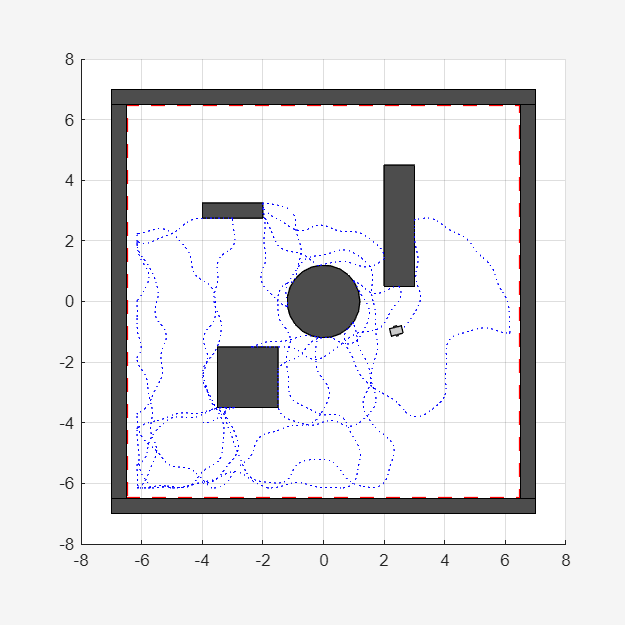

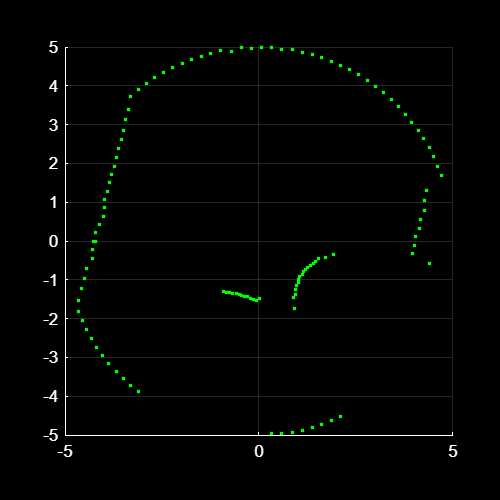

    % =============================================================
    % FORCE EXTERNAL PLOT WINDOW
    % =============================================================
    % Explicitly set WindowStyle to 'normal' to pop out of Live Script
    f = figure('Name', 'Summit-XL High Precision EKF', ...
               'WindowStyle', 'normal', ... 
               'Position', [100, 100, 1100, 500]);
    set(f, 'Visible', 'on');
    
    % Setup Subplots
    subplot(1,2,1); 
    h_scan = scatter(0, 0, 15, 'b', 'filled'); 
    hold on; grid on; axis equal;
    axis([-5 5 -5 5]); 
    title('360° LiDAR Scan (Robot Frame)');
    
    subplot(1,2,2); 
    h_gt = plot(0, 0, 'r-', 'LineWidth', 2); hold on; 
    h_est = plot(0, 0, 'g--', 'LineWidth', 1.5); 
    grid on; axis equal;
    legend('Ground Truth', 'EKF Estimate');
    title('Trajectory Tracking');
    

**Sensor Data Acquisition:** Collects data from encoders and IMU (angular velocity). Noise is added to simulate real-world sensor imperfections. 

    % --- Main Loop ---
    traj_gt_x = []; traj_gt_y = [];

Simulation Stopped.


    traj_ekf_x = []; traj_ekf_y = [];
    
    disp('Running EKF Loop...');
    
    for k = 1:1200
        if ~ishandle(f), break; end % Check if user closed the external window
        
        sim.step();
        
        % 1. SENSOR DATA ACQUISITION
        [linVel, angVel] = sim.getObjectVelocity(robot);
        if iscell(angVel), v_ang = cell2mat(angVel); else, v_ang = angVel; end
        
        currL = sim.getJointPosition(wheelFL);
        currR = sim.getJointPosition(wheelFR);
        
        dL = r * (currL - prevL);
        dR = r * (currR - prevR);
        
        v_enc = ((dL - dR) / (2 * dt)) + randn()*0.005; 
        gyroZ = v_ang(3) + randn()*0.002; 
        
        prevL = currL; prevR = currR;



**EKF Prediction Step**: Predicts the next robot state using motion equations. This step estimates where the robot should be based on movement.

        % 2. EKF PREDICTION
        theta_old = xEst(3);
        xPred = xEst + [v_enc*cos(theta_old)*dt; v_enc*sin(theta_old)*dt; gyroZ*dt];
        
        Fx = [1, 0, -v_enc*sin(theta_old)*dt; 
              0, 1,  v_enc*cos(theta_old)*dt; 
              0, 0, 1];
          
        PPred = Fx * PEst * Fx' + Q;

**LiDAR Scanning (Measurement Source):** Performs a 360° scan to detect surroundings. These measurements provide external information to correct the predicted state.

        % 3. LIDAR SCANNING
        scan_points = [];
        num_steps = 24; 
        for i = 1:num_steps
            angle = (i-1) * (2*pi/num_steps);
            sim.setJointPosition(lidarJoint, angle);
            
            [res, dist, ~, ~, ~] = sim.checkProximitySensor(lidarRay, sim.handle_all);
            
            if res > 0
                scan_points = [scan_points; dist*cos(angle), dist*sin(angle)]; %#ok<AGROW>
            end
        end

Launching CoppeliaSim...


**EKF Update Step (Correction):** Corrects the predicted state using measurement data. This step reduces error by combining prediction with observation.

        % 4. EKF UPDATE
        pos_gt_cell = sim.getObjectPosition(robot, -1);
        if iscell(pos_gt_cell), pos_gt = cell2mat(pos_gt_cell); else, pos_gt = pos_gt_cell; end
        
        z = [pos_gt(1); pos_gt(2)] + randn(2,1)*0.01; 
        
        H = [1, 0, 0; 0, 1, 0];
        y = z - H*xPred;
        S = H * PPred * H' + R;
        K = PPred * H' / S;
        
        xEst = xPred + K * y;
        PEst = (eye(3) - K * H) * PPred;

Loading scene...


Starting Loop...


**Visualization (Localization Result):** Displays LiDAR scan and compares estimated trajectory with ground truth. This helps evaluate the performance of the EKF.

        % 5. VISUALIZATION
        traj_gt_x = [traj_gt_x; pos_gt(1)]; 
        traj_gt_y = [traj_gt_y; pos_gt(2)];
        traj_ekf_x = [traj_ekf_x; xEst(1)]; 
        traj_ekf_y = [traj_ekf_y; xEst(2)];
        
        if ~isempty(scan_points)
            set(h_scan, 'XData', scan_points(:,1), 'YData', scan_points(:,2));
        end
        set(h_gt, 'XData', traj_gt_x, 'YData', traj_gt_y);
        set(h_est, 'XData', traj_ekf_x, 'YData', traj_ekf_y);
        
        title(subplot(1,2,2), sprintf('Step %d | Error: %.4f m', k, norm(pos_gt(1:2)' - xEst(1:2))));
        drawnow limitrate;
        
        % Stop condition check
        if sim.getSimulationState() == sim.simulation_stopped
            break;
        end
    end
    
    % --- Stop Simulation ---
    disp('Stopping...');
    sim.setJointTargetVelocity(wheelFL, 0);
    sim.setJointTargetVelocity(wheelFR, 0);
    sim.setJointTargetVelocity(wheelBL, 0);
    sim.setJointTargetVelocity(wheelBR, 0);
    sim.stopSimulation();
    disp('SIMULATION FINISHED.');

catch ME
    % --- Cleanup on Error ---
    warning('An error occurred: %s', ME.message);
    if exist('sim', 'var')
        sim.stopSimulation();
    end
end

## Simultaneous Localization and Mapping (SLAM)

Localization refers to estimating the robot’s position (and trajectory) given a known map. Mapping refers to constructing the map given the true robot trajectory. SLAM aims to estimate both the robot trajectory and the environment map simultaneously, using only noisy proprioceptive and exteroceptive sensor data. Typical inputs include:

- odometry-derived motion estimates,

- extracted features such as corners, edges, or planes from lidar, ultrasonic, or camera measurements.

Let the robot pose at time $t$ be denoted b $x_t$. The entire robot trajectory (path) up to time $T$ is therefore represented as  $X_{1:T} = \{x_1, x_2, \ldots, x_T\}.$ In the SLAM formulation, the initial pose $x_1$ is assumed to be known, whereas all subsequent poses are unknown. Let  $u_{t\;}$ denote the robot motion between time $t-1$ and $t$. These data may come from proprioceptive sensors such as wheel encoders or from the commanded control inputs to the motors. The sequence of robot motions is written as $U_{1:T} = \{u_1, u_2, \ldots, u_T\}.$ Let the true map of the environment be denoted by $M = \{ m_0, m_1, \ldots, m_{n-1} \},$ where each $m_i$ represents the location or parameters of a landmark. For simplicity, we assume the map is static. Suppose the robot obtains one measurement at each time step. Let $Z_{1:T} = \{z_1, z_2, \ldots, z_T\}$be the sequence of landmark observations expressed in the robot’s sensor coordinate frame. 

SLAM is defined as the problem of estimating both the map $M$ and the robot trajectory $X_{1:T}$, given only the motion inputs $U_{1:T}$ and the observations $Z_{1:T}$. The SLAM problem can be bifurcated into two types:

**1. Full SLAM Problem: **The full SLAM problem seeks the posterior distribution over the entire robot path and the map $ p(X_{1:T}, M \mid Z_{1:T}, U_{1:T}).$

**2. Online SLAM Problem: **The online SLAM problem seeks the posterior distribution over only the current pose and the map $p(x_T, M \mid Z_{1:T}, U_{1:T}). $

The motion model represents the probability of transitioning from pose $x_{t-1}$ to $x_t$ given the control input $u_t :$$p(x_t \mid x_{t-1}, u_t).$ The measurement model represents the probability of obtaining measurement $z_t$ given the robot pose $x_t$ and the map $M:$$p(z_t \mid x_t, M)$. These two models form the foundation of all probabilistic SLAM algorithms.

**MATLAB Code Example**

 **Initialization and Robot Parameters**: This block sets up the simulation timing, robot geometry, and LiDAR properties. It defines how the robot moves, how the sensor behaves, and how the map will be built.

%% ---------------- INITIALIZATION ----------------
com.mathworks.services.Prefs.setBooleanPref('LiveEditorFigureVisible', false);
close all; clc;

dt = 0.1;                   
mapRes = 0.1;               
mapSize = 22;      
mapBounds = [-6.5, 6.5, -6.5, 6.5];

bodyL = 0.4; bodyW = 0.25;
wheelR = 0.05; wheelW = 0.03; 
L_track = 0.3;
colRad = 0.35; 

bodyShape = [-bodyL/2, -bodyW/2; -bodyL/2,  bodyW/2;
              bodyL/2,  bodyW/2;  bodyL/2, -bodyW/2]';
wheelShape = [-wheelR, -wheelW/2; -wheelR,  wheelW/2;
               wheelR,  wheelW/2;  wheelR, -wheelW/2]';

v_cruise = 0.20;            
w_max = 0.35;               
noise_lidar = 0.02;    

**LiDAR Configuration:** Defines how the LiDAR sensor scans the environment. This includes range, number of rays, and angular coverage, which directly affect map quality.

lidarRange = 5.0;           
numRays = 120;               
fov = deg2rad(360);
lidar_angles = linspace(-fov/2, fov/2, numRays);


**Environment and Obstacles:** Builds a simulated world using walls and obstacles. These shapes define what the robot will perceive through LiDAR.

%% ---------------- ENVIRONMENT ----------------
obstacles = {};
thickness = 0.5;

obstacles{end+1} = getRectPoly(mapBounds(1)-thickness/2, 0, thickness, 14);
obstacles{end+1} = getRectPoly(mapBounds(2)+thickness/2, 0, thickness, 14);
obstacles{end+1} = getRectPoly(0, mapBounds(4)+thickness/2, 14, thickness);
obstacles{end+1} = getRectPoly(0, mapBounds(3)-thickness/2, 14, thickness);

obstacles{end+1} = getRectPoly(-2.5, -2.5, 2.0, 2.0); 
obstacles{end+1} = getRectPoly(2.5, 2.5, 1.0, 4.0);   
obstacles{end+1} = getCirclePoly(0, 0, 1.2, 24);      
obstacles{end+1} = getRectPoly(-3, 3, 2.0, 0.5);      

all_segments = [];
for i = 1:length(obstacles)
    P = obstacles{i};
    for j = 1:size(P,2)-1
        all_segments = [all_segments; P(1,j), P(2,j), P(1,j+1), P(2,j+1)];
    end
end

mapWidth = ceil(mapSize / mapRes);
occupancyMap = zeros(mapWidth, mapWidth); 
mapOrigin = [-mapSize/2, -mapSize/2]; 

%% ---------------- FIGURES (FORCED EXTERNAL) ----------------
f1 = figure('Name','1. Real World (Ground Truth)', ...
            'WindowStyle','normal', ...
            'Position',[50 400 500 500]);
set(f1,'Visible','on');
ax1 = axes('Parent',f1); hold(ax1,'on'); axis(ax1,'equal'); grid(ax1,'on');
xlim(ax1,[-8 8]); ylim(ax1,[-8 8]);

rectangle(ax1,'Position',[mapBounds(1),mapBounds(3), ...
    mapBounds(2)-mapBounds(1), mapBounds(4)-mapBounds(3)], ...
    'EdgeColor','r','LineWidth',2,'LineStyle','--');

for i = 1:length(obstacles)
    fill(ax1, obstacles{i}(1,:), obstacles{i}(2,:), ...
        [0.3 0.3 0.3],'EdgeColor','k');
end

h_traj = animatedline('Parent', ax1, 'Color', 'b', 'LineStyle', ':');
h_body = patch('Parent', ax1);
h_wL   = patch('Parent', ax1);
h_wR   = patch('Parent', ax1);

f2 = figure('Name','2. Lidar View', ...
            'WindowStyle','normal', ...
            'Color','k', ...
            'Position',[560 400 400 400]);
set(f2,'Visible','on');
ax2 = axes('Parent',f2); hold(ax2,'on'); axis(ax2,'equal'); grid(ax2,'on');
set(ax2,'Color','k','XColor','w','YColor','w');
xlim(ax2,[-5 5]); ylim(ax2,[-5 5]);
h_scan = plot(ax2,0,0,'g.','MarkerSize',6);

f3 = figure('Name','3. Occupancy Grid', ...
            'WindowStyle','normal', ...
            'Position',[970 400 400 400]);
set(f3,'Visible','on');
ax3 = axes('Parent',f3); hold(ax3,'on'); axis(ax3,'equal');
h_map = imagesc(ax3,'XData',[mapOrigin(1) mapOrigin(1)+mapSize], ...
    'YData',[mapOrigin(2) mapOrigin(2)+mapSize], ...
    'CData',occupancyMap);
colormap(ax3,flipud(gray)); axis(ax3,'xy');
h_rob_est = plot(ax3,0,0,'r^','MarkerFaceColor','r');


**The Main Loop:** This main loop runs the full simulation by repeatedly updating the robot’s motion, sensing, and visualization until any figure is closed. It starts with a true pose (ground truth) and an estimated pose (odometry), then at each time step generates a forward velocity and a slowly varying random angular velocity to create exploratory motion. A candidate next position is computed using standard differential-drive kinematics, and a simple collision check ensures the robot stays within map bounds; if a collision is detected, the robot reverses and turns to avoid obstacles, otherwise it proceeds normally. The estimated pose is updated using the same motion model, which introduces drift over time. Next, a full LiDAR scan is simulated by casting rays in all directions, computing intersections with environment segments, and adding noise to mimic real sensors. The occupancy map is converted from log-odds to probability for display. Finally, all visual elements are updated: the robot body (via a rotation matrix transform), its trajectory, the LiDAR scan in sensor space, the occupancy grid map, and the estimated robot position. The loop runs in real time using `drawnow`, advancing time step-by-step, and stops cleanly when the user closes any visualization window.

%% ---------------- MAIN LOOP ----------------
true_pose = [-4; -4; 0];
est_pose  = true_pose;
t = 0;
w_target = 0;

disp('Simulation Running... Close any figure to stop.')

while ishandle(f1) && ishandle(f2) && ishandle(f3)

    if mod(t,4) < dt
        w_target = w_max*(rand-0.5)*2;
    end

    v_cmd = v_cruise;
    w_cmd = 0.8*w_target + 0.2*sin(t);

    cand_x = true_pose(1) + v_cmd*cos(true_pose(3))*dt;
    cand_y = true_pose(2) + v_cmd*sin(true_pose(3))*dt;
    cand_th = true_pose(3) + w_cmd*dt;

    collision = false;

    if cand_x < mapBounds(1)+colRad || cand_x > mapBounds(2)-colRad || ...
       cand_y < mapBounds(3)+colRad || cand_y > mapBounds(4)-colRad
        collision = true;
    end
    for i = 1:length(obstacles)
        poly = obstacles{i};
        if inpolygon(cand_x, cand_y, poly(1,:), poly(2,:))
            collision = true;
            break;
        end
    end

    if collision
        v_actual = -0.05;
        w_actual = w_max;
        true_pose(1) = true_pose(1) + v_actual*cos(true_pose(3))*dt;
        true_pose(2) = true_pose(2) + v_actual*sin(true_pose(3))*dt;
        true_pose(3) = true_pose(3) + w_actual*dt;
    else
        v_actual = v_cmd;
        w_actual = w_cmd;
        true_pose = [cand_x; cand_y; cand_th];
    end

    est_pose(1) = est_pose(1) + v_actual*cos(est_pose(3))*dt;
    est_pose(2) = est_pose(2) + v_actual*sin(est_pose(3))*dt;
    est_pose(3) = est_pose(3) + w_actual*dt;

    ranges = zeros(1,numRays);
    global_angles = true_pose(3) + lidar_angles;

    for i = 1:numRays
        ray_dir = [cos(global_angles(i)), sin(global_angles(i))];
        min_dist = lidarRange;

        for j = 1:size(all_segments,1)
            p1 = all_segments(j,1:2);
            p2 = all_segments(j,3:4);
            [d, valid] = rayIntersect(true_pose(1:2)', ray_dir, p1, p2);
            if valid && d < min_dist
                min_dist = d;
            end
        end

        ranges(i) = min(min_dist + randn*noise_lidar,lidarRange);
    end
    for i = 1:numRays
    
        angle = global_angles(i);
        r = ranges(i);
        
        % Endpoint (occupied cell)
        x_end = true_pose(1) + r*cos(angle);
        y_end = true_pose(2) + r*sin(angle);
        
        ix = round((x_end - mapOrigin(1)) / mapRes);
        iy = round((y_end - mapOrigin(2)) / mapRes);
        
        if ix >= 1 && ix <= mapWidth && iy >= 1 && iy <= mapWidth
            occupancyMap(iy, ix) = occupancyMap(iy, ix) + 1.5;
        end
        
        % Free space along ray
        steps = linspace(0, r, 20);
        for s = steps
            xf = true_pose(1) + s*cos(angle);
            yf = true_pose(2) + s*sin(angle);
            
            ix = round((xf - mapOrigin(1)) / mapRes);
            iy = round((yf - mapOrigin(2)) / mapRes);
            
            if ix >= 1 && ix <= mapWidth && iy >= 1 && iy <= mapWidth
                occupancyMap(iy, ix) = occupancyMap(iy, ix) - 0.5;
            end
        end
    end
    probMap = 1 - 1./(1+exp(occupancyMap));

    if isgraphics(h_body)
        updateDiffRobot(true_pose,L_track,bodyShape,wheelShape,h_body,h_wL,h_wR);
    end

    if isgraphics(h_traj)
        addpoints(h_traj,true_pose(1),true_pose(2));
    end

    if isgraphics(h_scan)
        set(h_scan,'XData',ranges.*cos(lidar_angles), ...
                   'YData',ranges.*sin(lidar_angles));
    end

    if isgraphics(h_map)
        set(h_map,'CData',probMap);
    end

    if isgraphics(h_rob_est)
        set(h_rob_est,'XData',est_pose(1),'YData',est_pose(2));
    end

    drawnow limitrate
    t = t + dt;
end

disp('Simulation Stopped.')

function updateDiffRobot(pose,L,bodyShape,wheelShape,h_body,h_wL,h_wR)
x=pose(1); y=pose(2); th=pose(3);
R=[cos(th) -sin(th); sin(th) cos(th)];
bg=R*bodyShape+[x;y];
set(h_body,'XData',bg(1,:),'YData',bg(2,:), ...
    'FaceColor',[0.8 0.8 0.8],'EdgeColor','k');
wLg=R*(wheelShape+[0;L/2])+[x;y];
set(h_wL,'XData',wLg(1,:),'YData',wLg(2,:), ...
    'FaceColor','k');
wRg=R*(wheelShape+[0;-L/2])+[x;y];
set(h_wR,'XData',wRg(1,:),'YData',wRg(2,:), ...
    'FaceColor','k');
end

function P = getRectPoly(cx,cy,w,h)
x1=cx-w/2; x2=cx+w/2;
y1=cy-h/2; y2=cy+h/2;
P=[x1 x2 x2 x1 x1; y1 y1 y2 y2 y1];
end

function P = getCirclePoly(cx,cy,r,n)
t=linspace(0,2*pi,n);
P=[cx+r*cos(t); cy+r*sin(t)];
end

function [dist,valid]=rayIntersect(ro,rd,p1,p2)
v1=ro-p1; v2=p2-p1; v3=[-rd(2) rd(1)];
d=dot(v2,v3);
if abs(d)<1e-6, dist=inf; valid=false; return; end
t1=(v2(1)*v1(2)-v2(2)*v1(1))/d;
t2=dot(v1,v3)/d;
if t1>=0 && t2>=0 && t2<=1
    dist=t1; valid=true;
else
    dist=inf; valid=false;
end
end


### Extended Kalman Filter (EKF) SLAM

The EKF perates on an extended state vector $y_t$ would be $3+2n$ , since the robot pose $(x, y, \theta)
$ equires 3 parameters, and each of the $n$landmarks has 2 parameters. In this case, the full state vector would be written as $y_t =  [x_t,\, y_t,\, \theta_t,\, \alpha_0, r_0,\, \alpha_1, r_1,\, \ldots,\, \alpha_{n-1}, r_{n-1}]^{T}.$ As the robot moves and acquires observations, the joint state vector $y_t$ and its associated covariance matrix are updated using the standard EKF prediction and correction equations. EKF-SLAM naturally supports feature-based maps (points, lines, planes, etc.). As new landmarks are detected, they are appended to the state vector, causing the covariance matrix to grow quadratically in size $(3 + 2n) \times (3 + 2n).$ For computational reasons, EKF-SLAM is typically limited to fewer than a thousand features. 

The EKF-SLAM prediction model becomes:$x_{t+1} = \pmatrix{
 x_t + \Delta s \cos(\theta_t + \Delta \theta/2) \cr
y_t + \Delta s \sin(\theta_t + \Delta \theta/2) \cr
\theta_t + \Delta \theta 
}, $ and the Jacobian matrix for the prediction step is given by $F_t = \pmatrix{ F_{r,t} & 0 \cr
0 & I 
},
$ where $F_{r,t}$ is the Jacobian of the motion model with respect to the robot pose, $I$  is the identity matrix corresponding to fixed map features.

**CoppeliaSim Code Example**

**Configuration and Environment Setup:** This block prepares MATLAB and connects it to CoppeliaSim by locating the simulator, API, and scene file. It ensures everything is ready before running SLAM.

 

% =============================================================
% SUMMIT-XL HIGH-DENSITY SLAM MAPPER (Final Fix)
% Scene: localisation scene.ttt
% Controls: 1. RUN 2. CLICK THE POP-UP WINDOW 3. Use W/A/S/D
% =============================================================
clc; clear; close all force;

%% 1. CONFIGURATION & SETUP
coppeliaRoot = getenv('COPPELIA_ROOT');
if isempty(coppeliaRoot)
    error('Error: COPPELIA_ROOT environment variable not found.');
end

apiPath = fullfile(coppeliaRoot, 'programming', 'zmqRemoteApi', 'clients', 'matlab');
exePath = fullfile(coppeliaRoot, 'coppeliaSim.exe');
addpath(apiPath);

if matlab.desktop.editor.isEditorAvailable
    currentScriptPath = fileparts(matlab.desktop.editor.getActiveFilename);
else
    currentScriptPath = pwd;
end
sceneFile = fullfile(currentScriptPath, 'scenes', 'localisation scene.ttt');

%% 2. LAUNCH & CONNECT
disp('Launching CoppeliaSim...');
system(['start "" "' exePath '"']);
pause(4); 

client = RemoteAPIClient();
sim = client.getObject('sim');

%% 3. MAIN SIMULATION ROUTINE
try
    disp('Loading scene...');
    if isfile(sceneFile), sim.loadScene(sceneFile); end
    pause(1);

    % --- Get Handles (Consistent with Localization Example) ---
    robot = sim.getObject('/summit_xl');
    try
        wheelFL = sim.getObject('/summit_xl_front_left_wheel');
        wheelFR = sim.getObject('/summit_xl_front_right_wheel');
        wheelBL = sim.getObject('/back_left_wheel'); 
        wheelBR = sim.getObject('/back_right_wheel');
    catch
        wheelFL = sim.getObject('/summit_xl/front_left_wheel_joint');
        wheelFR = sim.getObject('/summit_xl/front_right_wheel_joint');
        wheelBL = sim.getObject('/summit_xl/back_left_wheel_joint');
        wheelBR = sim.getObject('/summit_xl/back_right_wheel_joint');
    end

    try
        lidarJoint = sim.getObject('/summit_xl/LiDAR/joint');
        lidarRay   = sim.getObject('/summit_xl/LiDAR/laser');
    catch
        lidarJoint = sim.getObject('/summit_xl/Hokuyo_URG_04LX_UG01');
        lidarRay   = lidarJoint; 
    end

**Map Initialization and Robot State: **Initializes the robot’s estimated position and creates the occupancy grid map where SLAM will be performed.

    % --- Map & Position Setup ---
    startPosCell = sim.getObjectPosition(robot, -1);
    startPos = cell2mat(startPosCell);
    xEst = [startPos(1); startPos(2); 0]; 
    dt = 0.05; r = 0.165; L = 0.582;
    mapSize = 20; res = 0.1; gridN = round(mapSize/res);
    occMap = 0.5 * ones(gridN, gridN); 

** Visualization and User Control Setup**: Creates an external interactive window for mapping and **enables keyboard control (W/A/S/D) for manual robot driving.**

    % =============================================================
    % FORCE EXTERNAL PLOT WINDOW (Bypassing Live Script Docking)
    % =============================================================
    set(0, 'DefaultFigureWindowStyle', 'normal'); 
    
    f = figure('Name', 'Summit-XL Mapper (EXTERNAL)', ...
               'WindowStyle', 'normal', ... 
               'Position', [100, 100, 800, 800]);
    set(f, 'Visible', 'on');
    
    % Keyboard Callbacks
    userData.currentKey = 'none';
    set(f, 'UserData', userData);
    set(f, 'KeyPressFcn', @(src, event) updateKey(src, event, true));
    set(f, 'KeyReleaseFcn', @(src, event) updateKey(src, event, false));
    
    ax = axes('Parent', f);
    h_map = imagesc(ax, [-mapSize/2 mapSize/2], [-mapSize/2 mapSize/2], occMap);
    colormap(gray); colorbar; set(ax, 'YDir', 'normal'); hold(ax, 'on');
    h_path = plot(ax, xEst(1), xEst(2), 'y-', 'LineWidth', 1.5); 
    h_rob = plot(ax, xEst(1), xEst(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    axis(ax, 'equal'); title(ax, 'CLICK HERE -> DRIVE WITH WASD');

    % Force window to top
    shg;
    drawnow;

    % --- Start Simulation ---
    disp('Starting Loop...');
    sim.setStepping(true);
    sim.startSimulation();
    
    traj_x = xEst(1); traj_y = xEst(2);

**Main Control, Odometry, and Mapping Loop**: This loop runs the full SLAM process in real time by combining user control, motion estimation, LiDAR sensing, and map updates until the simulation window is closed or the user exits.

This loop continuously executes while the figure window is active, first reading keyboard input (W/A/S/D) to generate linear and angular velocities for skid-steer motion, which are converted into wheel velocities and applied to the robot. After advancing the simulation one step, the robot’s pose is updated using odometry (dead reckoning), which estimates position based on motion and gradually accumulates drift. Next, a dense LiDAR scan is performed by rotating the sensor through multiple angles; for each ray, the code checks for obstacle detection, computes the endpoint in world coordinates, and converts it into grid indices. Using the Bresenham algorithm, all cells along each ray are updated in the occupancy grid—free space is reinforced along the ray path, while detected obstacle endpoints are marked as occupied. Finally, the map, robot position, and trajectory are updated visually in real time, allowing users to observe how motion and sensing build the environment map. The loop exits safely if the user presses ‘q’, closes the window, or the simulation stops, after which the simulator is shut down cleanly.

    
    while ishandle(f)
        uData = get(f, 'UserData');
        key = uData.currentKey;
        if strcmp(key, 'q'), break; end
        
        % 1. Control (Skid Steer)
        v = 0; w = 0;
        if strcmp(key, 'w'), v = 0.5; end
        if strcmp(key, 's'), v = -0.5; end
        if strcmp(key, 'a'), w = 0.8; end
        if strcmp(key, 'd'), w = -0.8; end
        
        wl = (v - w*L/2)/r; wr = (v + w*L/2)/r;
        sim.setJointTargetVelocity(wheelFL, wl); sim.setJointTargetVelocity(wheelBL, wl);
        sim.setJointTargetVelocity(wheelFR, -wr); sim.setJointTargetVelocity(wheelBR, -wr); 
        
        sim.step();
        
        % 2. Odometry (Dead Reckoning)
        theta = xEst(3);
        xEst = xEst + [v*cos(theta)*dt; v*sin(theta)*dt; w*dt];
        traj_x = [traj_x; xEst(1)]; traj_y = [traj_y; xEst(2)];
        
        % 3. Dense Mapping (Ray Casting)
        num_steps = 20; 
        for i = 1:num_steps
            angle = (i-1) * (2*pi/num_steps);
            sim.setJointPosition(lidarJoint, angle);
            [res_lidar, dist] = sim.checkProximitySensor(lidarRay, sim.handle_all);
            
            x0 = round((xEst(1) + mapSize/2) / res);
            y0 = round((xEst(2) + mapSize/2) / res);
            
            % FIXED: Consolidated variable name to 'rayDist'
            rayDist = 6.0; 
            isHit = false;
            if res_lidar > 0
                rayDist = dist; 
                isHit = true; 
            end
            
            gx = xEst(1) + rayDist * cos(xEst(3) + angle);
            gy = xEst(2) + rayDist * sin(xEst(3) + angle);
            x1 = round((gx + mapSize/2) / res);
            y1 = round((gy + mapSize/2) / res);
            
            [px, py] = bresenham_slam(x0, y0, x1, y1);
            for p = 1:length(px)
                if px(p)>0 && px(p)<=gridN && py(p)>0 && py(p)<=gridN
                    if isHit && p == length(px)
                        occMap(py(p), px(p)) = max(occMap(py(p), px(p)) - 0.3, 0); 
                    else
                        occMap(py(p), px(p)) = min(occMap(py(p), px(p)) + 0.1, 1); 
                    end
                end
            end
        end
        
        % 4. Render
        if ishandle(h_map)
            set(h_map, 'CData', occMap);
            set(h_rob, 'XData', xEst(1), 'YData', xEst(2));
            set(h_path, 'XData', traj_x, 'YData', traj_y);
            drawnow limitrate;
        end
        
        if sim.getSimulationState() == sim.simulation_stopped, break; end
    end
    
    sim.stopSimulation();
    disp('Finished.');

catch ME
    warning('Error: %s', ME.message);
    if exist('sim','var'), sim.stopSimulation(); end
end

**Helper Functions**: Provides utility functions for keyboard handling and ray tracing.

%% HELPERS
function updateKey(src, event, isPressed)
    uData = get(src, 'UserData');
    if isPressed, uData.currentKey = event.Key; else, uData.currentKey = 'none'; end
    set(src, 'UserData', uData);
end

function [x, y] = bresenham_slam(x1, y1, x2, y2)
    x1=round(x1); x2=round(x2); y1=round(y1); y2=round(y2);
    dx=abs(x2-x1); dy=abs(y2-y1); steep=abs(dy)>abs(dx);
    if steep, [x1, y1] = deal(y1, x1); [x2, y2] = deal(y2, x2); end
    if x1>x2, [x1, x2] = deal(x2, x1); [y1, y2] = deal(y2, y1); end
    dx=x2-x1; dy=abs(y2-y1); error=dx/2; ystep=-1; if y1<y2, ystep=1; end
    y=zeros(1, x2-x1+1); x=zeros(1, x2-x1+1); currY=y1; idx=1;
    for currX = x1:x2
        if steep, x(idx)=currY; y(idx)=currX; else, x(idx)=currX; y(idx)=currY; end
        error=error-dy; if error<0, currY=currY+ystep; error=error+dx; end
        idx=idx+1;
    end
end

### Visual SLAM with a Single Camera

Visual SLAM or V-SLAM can be regarded as a multiview Structure-from-Motion (SfM) problem which aims to recover the camera motion and the 3D structure of the environment from a sequence of monocular images by tracking visual features. The key difference is that **V-SLAM explicitly models uncertainty** using a probabilistic framework, while classical SfM does not. Additionally, V-SLAM processes frames **sequentially**, whereas SfM can operate on unordered image collections. 

One major difficulty in monocular V-SLAM is the initialization of feature depths when the system starts. With a range sensor, this is trivial, but a single camera cannot determine depth from a single image. To address this, a **planar calibration pattern** with known geometry is used. If the image contains at least **four 2D–3D correspondences**, the full 6-DoF camera pose relative to the pattern can be computed uniquely. This is known as the **camera pose estimation** problem. As long as the camera views the calibration pattern, its pose can be estimated directly from each image. Once the camera moves away from the pattern, new features are **triangulated** and added to the map, and the EKF V-SLAM process begins. 

**State Representation and EKF Formulation: **In EKF V-SLAM, the state vector $y_t$ contains:

- camera position $r_t$ (3 parameters)

- camera orientation $q_t$ (unit quaternion, 4 parameters)

- translational velocity $v_t$ (3 parameters)

- angular velocity $\omega_t$ (3 parameters)

- positions of all $n$ point features $m_i$ (each 3D)

Thus, the state vector dimension is $\dim(y_t) = 13 + 3n.$ The full state vector is given by $y_t = [r_t,\ q_t,\ v_t,\ \omega_t,\ m_0,\ m_1,\ldots,m_{n-1}]^\top .$ 

**Prediction Step: **Because V-SLAM does not use odometry, a constant-velocity motion model is used. Between consecutive frames, the camera motion is predicted by integrating:

- the current translational velocity

- the current angular velocity

- small unknown accelerations modeled as zero-mean Gaussian noise

The prediction function$f$is given by:

 
$$r_{t+1} = r_t + (v_t + V)\Delta t,$$
 


$$q_{t+1} = q_t \otimes q\left((\omega_t + Q)\Delta t\right),$$


$v_{t+1} = v_t + V, \qquad \omega_{t+1} = \omega_t + Q,$ where $V = a\,\Delta t,  \qquad Q = \alpha\,\Delta t,$ and $a$ and $\alpha$ are unknown translational and angular accelerations modeled as Gaussian noise. The feature positions remain unchanged: $m_{i,t+1} = m_{i,t}.
$ This leads to the EKF prediction update: $y_{t+1|t} = \pmatrix{
 r_{t+1} \cr
q_{t+1} \cr
v_{t+1} \cr
\omega_{t+1} \cr
m_{0,t} \cr
m_{1,t} \cr
 
\vdots \cr
m_{n-1,t} }.$

**Measurement Update: **V-SLAM are visual interest points, such as corners or blobs, extracted using standard detectors. These features are expressed in image coordinates. The measurement function $h$ predicts the image location of each feature by:

- transforming the 3D feature point from world coordinates to the camera frame

- projecting the point onto the image plane using the calibrated camera model

For each feature, the EKF computes:

- its predicted pixel location

- the associated uncertainty ellipse

- the innovation between predicted and observed feature positions

New features are initialized (triangulated) and appended to the map. The standard EKF measurement-update equations then refine the camera state and all feature estimates.

### Graph-based SLAM

Most graph-based SLAM algorithms are designed to solve the full SLAM problem, although several variants exist for the online SLAM problem as well. The central idea behind graph-based SLAM is the observation that the SLAM problem can be formulated as a sparse graphical model composed of nodes and constraints: 

- Nodes correspond to robot poses $x_0, x_1, \ldots, x_T,$ and possibly to map features $m_0, m_1, \ldots, m_{n-1}.$

- Constraints represent relations between nodes, such as: (1) odometry constraints between successive poses $x_{t-1}$ and $x_t$ (given by motion input $u_t$), (2) observation constraints between robot poses and visible landmarks.

These constraints encode relative position measurements and their associated uncertainties.

### Particle Filter SLAM

Particle-filter-based SLAM approaches represent a third major paradigm for solving the SLAM problem. This family of methods is based on the randomized sampling representation of belief distributions. nlike EKF-based approaches that model the belief as a single Gaussian, particle-filter SLAM represents the distribution over possible robot trajectories using a set of weighted samples, or particles.

At each time step, the particle filter maintains a fixed number $K$ of particles (typically $K = 100 \ldots 1000$). Each particle contains:

- A **sampled robot path **$X^k_{1:t} = \{ x_1^k, x_2^k, \ldots, x_t^k \}$

- A **separate Gaussian estimate for each landmark** in the map: mean $\mu_{i,t}^k$ and covariance $\Sigma_{i,t}^k$

Thus, each particle is fully described as: $\pi_t^k =  \left( X^k_{1:t},\ \{ \mu_{i,t}^k,\ \Sigma_{i,t}^k \}_{i=1}^{n} \right), \qquad k = 1,\ldots,K .$

**Prediction Step: **When the robot moves, the motion model (derived from odometry input $u_t$) is applied independently to each particle: $x_t^k \sim p(x_t \mid x_{t-1}^k,\ u_t).$ This produces a new sampled pose for each particle, thereby propagating the robot path estimate forward.

The landmark estimates $\mu _{i,t-1}^k$ and $\Sigma_{i, t-1}^k$ remain unchanged during the prediction.

**Measurement Update: **When the robot makes an observation $z_t$, each particle computes an **importance weight**: $w_t^k = p(z_t \mid X^k_{1:t},\ z_{1:t-1}).$ 

## **Quiz**

1) A differential-drive robot moves with a forward wheel displacement of $$\Delta s_r = 1.05\text{ m}$$ and $$\Delta s_l = 0.95\text{ m}$$. The wheelbase is $$b = 0.5\text{ m}$$. Calculate the change in orientation $$\Delta \theta$$.

"0.2 rad"
switch ans
    case "0.2 rad"
        disp("Right Answer");
  
        
    otherwise
        disp("Wrong Answer.");
end

2) In an EKF-SLAM system, if the state vector contains the robot pose (3 DOF) and 100 point landmarks (2 DOF each), what is the size of the square covariance matrix $$\Sigma$$?

"203 X 203"
switch ans
    case "203 X 203"
        disp("Right Answer");
  
        
    otherwise
        disp("Wrong Answer.");
end

3) Why is the Extended Kalman Filter (EKF) used in robotics instead of the standard Kalman Filter?

"Because robot motion and sensor models are usually non-linear."
switch ans
    case "Because robot motion and sensor models are usually non-linear."
        disp("Right Answer");
  
        
    otherwise
        disp("Wrong Answer.");
end

## **Exercise**

1) A differential-drive robot (e.g., Pioneer P3DX) on a flat floor. Add a few static obstacles (cubes/cylinders) within range of the robot's sensors.

2) Initialize the robot pose to (0, 0, 0).

3) Drive the robot in a **Square Path**.

4) In a loop, read the **Wheel Joint Positions** (simulating encoders).

5)Calculate $$\Delta s_r, \Delta s_l$$, linear distance$ $\Delta s$$, and angular change $$\Delta \theta$$.

6) Plot this *Estimated Path* in Red. Simultaneously, read the *True Position* (Ground Truth) from the simulator using `sim.getObjectPosition` and plot it in Blue.

7) Run the robot on square path trajectory for 3 complete loops without resetting the pose.

8) Compare the "Red Line" (Odometry) and "Blue Line" (Ground Truth).

9) Analyse the average error.